% Path to the code/scripts
addpath(genpath('/Users/teatompos/Documents/GitHub/PhD_Project1--small-spiking-neural-network'))
addpath(genpath('/Users/teatompos/Desktop/Matlab_scripts/RU_1st_internship_Neurophysiology_Dept/DynaSim'))
clear all

% Saving names prefixes

SaveSim_pre = 'Fig2_Net_';
SaveAn_pre = 'Fig2_Analysis_';
SaveFig_pre = 'Fig2_';

% Path to save/retrieve results
% ResultsPath = '/Volumes/T7/Data/Fixed_CTXseed';
% addpath(genpath(ResultsPath))

Simulate = 0;
SaveResults = 0;

% cd(ResultsPath)

% Path to save/retrieve analysis
AnalysisPath = '/Users/teatompos/Library/CloudStorage/GoogleDrive-t.tompos@neurophysiology.nl/.shortcut-targets-by-id/1f3yqxuDDFP_-nrGlSKbqcVC3RJJZZWTiWyK5Kl5x65maOi21i1OEIloSOR_UsCfsdiH2FbZf/Lab notebook Tea Tompoš/Thesis/Chapter 2 (The model)/Analysis/ParamSensitivity/Fixed_CTXseed_analysis';
addpath(genpath(AnalysisPath))

BasicAnalysis = 0;
AdvancedAnalysis = 0;

SaveAnalysis = 0;

% Path to save figures
FiguresPath = '/Users/teatompos/Library/CloudStorage/GoogleDrive-t.tompos@neurophysiology.nl/.shortcut-targets-by-id/1f3yqxuDDFP_-nrGlSKbqcVC3RJJZZWTiWyK5Kl5x65maOi21i1OEIloSOR_UsCfsdiH2FbZf/Lab notebook Tea Tompoš/Thesis/Chapter 2 (The model)/Figures/Fig2_Fig3';
addpath(genpath(FiguresPath))

SaveFigures = 0;

% Scaling factors
synScalingFactors = [0.4:0.2:2.5];
pconnScalingFactors = [0.4:0.2:2.5];

% E-I ratio
Ecells_percentage = 0.85;
Icells_percentage = 0.15;

% Simulation time
tstop = 600;

% LIF neurons?
isLif = 0;

% Which seeds to use?
RandomSeeds = [4, 47, 49, 67, 30];
seeds = [];

% Repetition per seed
repetitions = 10;

if Simulate
    % limit the number of parallel workers because matlab runs out of memory
    delete(gcp('nocreate'))
    parpool('local', 6);
    
    cd(ResultsPath)
end

# Simulations

% Stimulate the same network with varying thalamic input

if Simulate
    for s_num = RandomSeeds(3)
        seeds.ctx_seed = s_num; % this will fix cortical connectivity
        seeds.vpm_seed = []; % this will let vpm vary across repetitions

        parfor synStr = 1:length(synScalingFactors)
            for pconn = 1:length(pconnScalingFactors)
                synParams = struct('synstr',[synScalingFactors(synStr) synScalingFactors(synStr)], ...
                    'pconn', [pconnScalingFactors(pconn) pconnScalingFactors(pconn)]);

                for r_num = 1:repetitions
                    NetSaveName = sprintf('%s_S%i_P%i_Rep%i_Seed%i', SaveSim_pre, round(synScalingFactors(synStr)*100), round(pconnScalingFactors(pconn)*100), r_num, s_num);
                    SpikingNetwork = SimN4(Ecells_percentage, Icells_percentage, [], synParams, [], [], 'synthetic', seeds, tstop);
                    SpikingNetwork.Seeds = seeds;
                    fprintf('Simulated %s. \n', NetSaveName)
                    
                    if SaveResults
                        cd(ResultsPath)
                        ParallelSave(NetSaveName,SpikingNetwork)
                    end

                end
            end
        end
    end
end

# Sanity check

% quick check if CTX is fixed
checkSims = 0;

cd '/Users/teatompos/Library/CloudStorage/GoogleDrive-t.tompos@neurophysiology.nl/.shortcut-targets-by-id/1f3yqxuDDFP_-nrGlSKbqcVC3RJJZZWTiWyK5Kl5x65maOi21i1OEIloSOR_UsCfsdiH2FbZf/Lab notebook Tea Tompoš/Thesis/Chapter 2 (The model)/Simulations/ParamSensitivity/Fixed_CTX_Seed'

if checkSims
    s_num = RandomSeeds(3);
    
    simNames = {'Fig2_Net__S100_P80_Rep6_Seed49';'Fig2_Net__S100_P80_Rep7_Seed49';'Fig2_Net__S100_P100_Rep1_Seed49';'Fig2_Net__S100_P100_Rep2_Seed49'};
    HistsToCompare = {}; % first collect all histograms
    figure; tiledlayout(2,2);
    
    for ii = 1:length(simNames)
        % compare connectivity
        a = load([simNames{ii} '.mat']);
        time = [a.SpikingNetwork.time(1) a.SpikingNetwork.time(end) a.SpikingNetwork.simulator_options.dt];
        combinedVPMpops = [a.SpikingNetwork.VPMcorr_V a.SpikingNetwork.VPMuncorr_V];
        ThisHist = plotPsthAndRaster('psth',getSpikeTimes(combinedVPMpops,[time(1):time(3):time(2)]),3,time(2),0);
        HistsToCompare{ii,1} = simNames{ii};
        HistsToCompare{ii,2} = ThisHist;
        HistsToCompare{ii,3} = a.SpikingNetwork.model.fixed_variables.L2E_L3I_iGABAa_netcon;
    end
    
    comp1 = 1;
    comp2 = 2;
    nexttile; imagesc( HistsToCompare{comp1,3} - HistsToCompare{comp2,3} );
    title({[HistsToCompare{comp1,1} ' -']; HistsToCompare{comp2,1}})
    colormap([0 0 0; 1 1 1; 1 0 0.5])
    colorbar; caxis([-1 1])
    
    comp1 = 1;
    comp2 = 3;
    nexttile; imagesc( HistsToCompare{comp1,3} - HistsToCompare{comp2,3} );
    title({[HistsToCompare{comp1,1} ' -']; HistsToCompare{comp2,1}})
    colormap([0 0 0; 1 1 1; 1 0 0.5])
    colorbar; caxis([-1 1])
    
    comp1 = 3;
    comp2 = 4;
    nexttile; imagesc( HistsToCompare{comp1,3} - HistsToCompare{comp2,3} );
    title({[HistsToCompare{comp1,1} ' -']; HistsToCompare{comp2,1}})
    colormap([0 0 0; 1 1 1; 1 0 0.5])
    colorbar; caxis([-1 1]) 
    
    % then compare all histograms
    nexttile; hold on;
    x_vec = 0:3:600;
    for mm = 1:length(HistsToCompare)
        plot(x_vec,HistsToCompare{mm,2});
    end
    legend(HistsToCompare(:,1))
    xlabel('Time (ms)')
    ylabel('Spikes')
    title('VPM activity')
    
    if SaveFigures
        cd(FiguresPath)
        f=gcf;
        set(f, 'paperorientation', 'landscape', 'renderer','painter')
        print(f,[SaveFig_pre '_sanityCheck_seed' num2str(s_num)], '-dpdf','-bestfit')
    end
end

Note that it makes sense that there is negative difference in the third subplot. Negative difference means that the subsequent connectivity matrix contains positive values where the current connectivity matrix contains zeros. That is because the subsequent connectivity matrix comes from the simulation condition with increased PConn.

# Analysis

% Basic analysis
s_num = RandomSeeds(3);

if BasicAnalysis
    % activate paralel cores
    delete(gcp('nocreate'))
    myCluster = parcluster('local');
    delete(myCluster.Jobs);
    parpool('local', 8);
    
    % save stuff here
    cd(AnalysisPath)
    
    % check if there is already something analysed
    fileNames = dir;
    fileIdx = cell2mat(cellfun(@(x) contains(x,['_Seed' num2str(s_num) '_backup']), {fileNames.name}, 'uniformoutput', false))';
    analysisNameExist = {fileNames(fileIdx).name}';
    
    for synStr = 1:length(synScalingFactors)
        failedStuff = [];
        newAn = 0;
    
        loadLabel = [SaveAn_pre '_S' num2str(round(synScalingFactors(synStr)*100)) '_'];
        if any(contains(analysisNameExist, loadLabel))
            fullLoadLabel = cell2mat(analysisNameExist(find(contains(analysisNameExist, loadLabel))));
    %         loadedData = ParallelLoad(fullLoadLabel);
            loadedData = load(fullLoadLabel);
            SNN_analysed = loadedData.SNN_analysed;
        else
            SNN_analysed = [];
        end
    
        for pconn = 1:length(pconnScalingFactors)
            for r_num = 1:repetitions
                NetSaveName = sprintf('%s_S%i_P%i_Rep%i_Seed%i', SaveSim_pre, round(synScalingFactors(synStr)*100), round(pconnScalingFactors(pconn)*100), r_num, s_num);
                try
                    if ~isempty(SNN_analysed) % check if something was already analysed
                        if ~any(contains(SNN_analysed.SimulationLabel, NetSaveName))
                            newAn = 1;
                        else
                            fprintf('Already analysed %s. \n', NetSaveName)
                        end
                    else % if SNN is empty
                        newAn = 1;
                    end
    
                    if newAn
                        fprintf('Loading %s. \n', NetSaveName)
    %                     loadedData = ParallelLoad(NetSaveName);
                        loadedData = load(NetSaveName);
                        SpikingNetwork = loadedData.SpikingNetwork;
    
                        SNN_analysed = [SNN_analysed; analyzeSparseSim(SpikingNetwork, NetSaveName)];
                        fprintf('Analysed %s. \n', NetSaveName)
    
                        % inermediate save
                        cd(AnalysisPath)
                        AnSaveName = sprintf('%s_S%i_Seed%i_backup', SaveAn_pre, round(synScalingFactors(synStr)*100), s_num);
    %                     ParallelSave(AnSaveName,SNN_analysed)
                        save(AnSaveName, 'SNN_analysed','-v7.3')
                    end
                    newAn = 0;
                catch ME
                    failedStuff{end+1,1} = NetSaveName;
                    failedStuff{end,2} = ME.message;
                end
            end
        end
        if SaveAnalysis
            cd(AnalysisPath)
            AnSaveName = sprintf('%s_S%i_Seed%i_full', SaveAn_pre, round(synScalingFactors(synStr)*100), s_num);
            save(AnSaveName, 'SNN_analysed','-v7.3')
        
            fprintf('Saved the following analysis: %s.\n', AnSaveName)
        end
        failedStuff
    end
end

% Advanced analysis
clearvars -except s_num synScalingFactors pconnScalingFactors Save* RandomSeeds AnalysisPath AdvancedAnalysis FiguresPath

if ~exist('s_num','var')
    s_num = RandomSeeds(3);
end

warning('off')

pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I'];

cd(AnalysisPath)

%this used to be function fitting  protocol but we abandoned it
if AdvancedAnalysis
    for synStr = synScalingFactors
        AnSaveName = sprintf('%s_S%i_Seed%i_full.mat', SaveAn_pre, round(synStr*100), s_num);
        load(AnSaveName)
        
        quant = [];
        for pconn = pconnScalingFactors
            for jj=1:length(pops)
                label = sprintf('%s_S%i_P%i_Rep', SaveSim_pre, round(synStr*100), round(pconn*100));
                tbl = SNN_analysed(strcmp(SNN_analysed.Population, pops(jj,:)) & contains(SNN_analysed.SimulationLabel, label),:);

                if ~isempty(tbl)
                    AllSim_AllEvents = []; % this will collect data for all events in one simulation
                    AllSim_PopXCorr = [];
                    noActivity = 0;
                    eventCount = 1;
                    for simNum = 1:size(tbl,1)
                        AllSim_PopXCorr(simNum,1).SimulationLabel = tbl.SimulationLabel{simNum, 1};
                        AllSim_PopXCorr(simNum,1).PopulationPSTH_XCorr = tbl.PopulationPSTH_XCorr{simNum,1};
                        AllSim_PopXCorr(simNum,1).PopulationPSTH_XCorrLags_inMs = tbl.PopulationPSTH_XCorrLags{simNum,1} * tbl.PSTHBinSize{simNum,1};
                        
                        for evNum = 1:length(tbl.VPMEventData{simNum,1})
                            AllSim_AllEvents(eventCount,1).SimulationLabel = tbl.SimulationLabel{simNum, 1};
                            
                            % look into events
                            binSize_events = tbl.PSTHBinSize{simNum, 1};
                            eventLength = 60/binSize_events;
                            pre_event = tbl.VPMEventData{simNum,1}{1, evNum}.StartTime;
                            peak_event = tbl.VPMEventData{simNum,1}{1, evNum}.PeakTime;
                            post_event = tbl.VPMEventData{simNum,1}{1, evNum}.EndTime;
                                                        
                            %% MAKE A HISTOGRAM
                            event_time_vec_precise = peak_event:binSize_events:post_event; % this one starts when the event time starts, not with the left edge
                            vpm_hist = histcounts(cell2mat(tbl.VPMEventData{simNum,1}{1, evNum}.VPMSpikes'), event_time_vec_precise);
                            ctx_hist = histcounts(cell2mat(tbl.VPMEventData{simNum,1}{1, evNum}.CTXTime'), event_time_vec_precise);
                            
                            if length(ctx_hist) < eventLength
                                % i pad only at the right side because all
                                % events start from the event peak; this
                                % means that it can not be too short on the
                                % left side
                                vpm_hist = [vpm_hist zeros([1 diff([length(vpm_hist) eventLength])])];
                                ctx_hist = [ctx_hist zeros([1 diff([length(ctx_hist) eventLength])])];
                            end
                            x_vec = ([0:length(ctx_hist)])*binSize_events;
                            
                            active_VPM = sum(cell2mat(cellfun(@(x) ~isempty(x), tbl.VPMEventData{simNum,1}{1, evNum}.VPMSpikes, 'uniformoutput', 0)));
                            FR_VPM = vpm_hist ./ active_VPM;
                            
                            AllSim_AllEvents(eventCount,1).VPM_hist = vpm_hist;
                            AllSim_AllEvents(eventCount,1).VPM_participating = active_VPM;
                            AllSim_AllEvents(eventCount,1).VPM_FR_participating = FR_VPM;
                            AllSim_AllEvents(eventCount,1).hist_time = x_vec;
                                
                            active_CTX = sum(cell2mat(cellfun(@(x) ~isempty(x), tbl.VPMEventData{simNum,1}{1, evNum}.CTXTime, 'uniformoutput', 0)));
                            
                            if any(ctx_hist>0)
                                %% GET FR 
                                FR_participating = ctx_hist ./ active_CTX; % new formula: FR = #spikes / N
                                FR_participating(isnan(FR_participating)) = 0;
                                
                                AllSim_AllEvents(eventCount,1).CTX_hist = ctx_hist;
                                AllSim_AllEvents(eventCount,1).CTX_participating = active_CTX;
                                AllSim_AllEvents(eventCount,1).CTX_FR_participating = FR_participating;
                                
                                %% GET TOTAL SPIKING ACTIVITY (INTEGRATE THE SIGNAL)
                                tot_spikes_participating = trapz(FR_participating);
                                
                                AllSim_AllEvents(eventCount,1).CTX_FR_participating_AUC = tot_spikes_participating;
                            else
                                noActivity = noActivity + 1;
                            end
                            eventCount = eventCount + 1;
                        end                 
                    end
                end
                quant = [quant; table({pops(jj,:)},{synStr},{pconn},{label},{AllSim_AllEvents},{AllSim_PopXCorr},'VariableNames',{'Population', 'SynStr', 'PConn', 'SimulationLabel', 'EventData', 'XCorrData'})];
            end
        end
        if SaveAnalysis
            save(sprintf('%s_S%i_EventData', SaveAn_pre, round(synStr*100)), 'quant','-v7.3')
        end
    end
end
return

# Results

## Figure 2a

smoothing = 3.5;

clearvars -except s_num SaveFigures SaveAn_pre SaveFig_pre FiguresPath pops s_num SaveSim_pre AnalysisPath smoothing

pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I'];
synScalingFactors = [0.4:0.2:2.5];
pconnScalingFactors = [0.4:0.2:2.5];

figure(1); clf; tiledlayout(2,3)
cd(AnalysisPath)

popSequence = [5 3 1 6 4 2];
newAnalysis = 0;

if newAnalysis
    Fig2_PlotData = [];
    saveNew = 1;
else
    load('Fig2_PlotDataAUC.mat')
    saveNew = 0;
end

for popSeq = 1:length(popSequence)
    jj = popSequence(popSeq);
    plotData = [];
    pop = pops(jj,:);

    if newAnalysis
        for synStr = synScalingFactors
            load(sprintf('%s_S%i_EventData_Seed%i.mat', SaveAn_pre, round(synStr*100), s_num))
            
            for pconn = pconnScalingFactors
                label = sprintf('%s_S%i_P%i_Rep', SaveSim_pre, round(synStr*100), round(pconn*100));
                tbl = quant(strcmp(quant.Population, pops(jj,:)) & contains(quant.SimulationLabel, label),:);
                dataPoints = [];
                
                if any(contains(fieldnames(tbl.EventData{1,1}), 'CTX_FR_participating'))
                    dataPoints = trapz(nanmean(cell2mat({tbl.EventData{1,1}.CTX_FR_participating}'),1));
                else
                    dataPoints = NaN;
                end
                plotData{find(synScalingFactors==synStr),find(pconnScalingFactors==pconn)} = dataPoints;
            end
        end
        plotDataFlat = cell2mat(plotData);

        Fig2_PlotData{popSeq} = plotDataFlat;
        
        plotDataFlat = plotDataFlat./max(max(plotDataFlat)); % normalize to the max;
    else
        plotDataFlat = Fig2_PlotData{1, popSeq};
        plotDataFlat = plotDataFlat./max(max(plotDataFlat)); % normalize to the max;
    end
  
    plotDataFlat(isnan(plotDataFlat)) = 0;
    
    %%% TOTAL SPIKING
    nexttile(popSeq);
    plotDataFlat = imgaussfilt(plotDataFlat, smoothing);
    h = pcolor_fleur(pconnScalingFactors, synScalingFactors, plotDataFlat);%
    set(h, 'EdgeColor', 'none', 'AlphaData', ~isnan(plotDataFlat), 'facecolor', 'flat');
    cb = colorbar;
    colormap(turbo(256));
    caxis([0, 0.8]);
    title(pop)
    ylabel(cb,'AUC / max(AUC)', 'Interpreter','none')

    xax = gca;
    xax.XTickMode = 'manual';
    xax.XTick = pconnScalingFactors;
    xax.XTickLabel = pconnScalingFactors;

    xax.YTickMode = 'manual';
    xax.YTick = synScalingFactors;
    xax.YTickLabel = synScalingFactors;
    xlabel('PConn scale')
    ylabel('SynStr scale')
end
if saveNew
    cd(AnalysisPath); save('Fig2_PlotDataAUC', 'Fig2_PlotData','-v7.3')
end

cols = [
    0 0 0;                   % Black
    0.9373  0.8157  0.6353;  % Lightish orange
    0.3882  0.3725  0.6353;  % Dark violet-blue
    1 0 1;                   % Magenta
];

if SaveFigures
    cd(FiguresPath)
    for ii=1:6; nexttile(ii); hold on;
        scatter(1,1,28,'filled','markerfacecolor',cols(1,:),'markeredgecolor',[1 1 1]);
        scatter(2,1,28,'filled','markerfacecolor',cols(2,:),'markeredgecolor',[1 1 1]); 
        scatter(1,2,28,'filled','markerfacecolor',cols(3,:),'markeredgecolor',[1 1 1]); 
        scatter(2,2,28,'filled','markerfacecolor',cols(4,:),'markeredgecolor',[1 1 1]); 
    end
    f=gcf;
    set(f, 'paperorientation', 'landscape', 'renderer','painter')
    print(f,[SaveFig_pre '_heatmap_TotSpikes_seed' num2str(s_num)], '-dpdf','-bestfit')
end

Observations:

- L2E: initial state (black dot) is functionally sparse, sits near the silent boundary; increasing the strength and connectivity probability has effectful impacts only at high scaling factors

- L2I: same as L2E

- L3E: same as L3E

- L3I: relatively more sensitive to the increase in connectivity parameters; reflects the activation pattern of the preceding excitatory population (L4E)

- L4E: initial state is closer to the unstable zone (green) where impacts of connectivity parameter increase are immediate

- L4I: same as in L4E but the hotspot of maximal activation (upper left corner) is almost mirrored compared to L4E (upper right corner)

- Superficial layers L2/3 robustly maintain low excitability despite increased synaptic weight and connectivity probability

Next, we focus on four highlighted cases. We ask what are the individual and combined contributions of increased synaptic weights and connectivity probabilities?

## Figure 2b

clearvars -except s_num SaveFigures SaveAn_pre SaveFig_pre FiguresPath pops s_num SaveSim_pre AnalysisPath smoothing Fig2_PlotData

pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I'];
synScalingFactors = [0.4:0.2:2.5];
pconnScalingFactors = [0.4:0.2:2.5];
popSequence = [5 3 1 6 4 2];

leftIdx = find(pconnScalingFactors==1);
rightIdx = find(pconnScalingFactors==2);
upIdx = find(synScalingFactors==2);
downIdx = find(synScalingFactors==1);

figure; clf; tiledlayout(3,2)
for popSeq = 1:length(popSequence)
    jj = popSequence(popSeq);
    pop = pops(jj,:);
    
    nexttile(jj); hold on;
    
    plotDataFlat = Fig2_PlotData{1, popSeq};
    plotDataFlat = plotDataFlat./max(max(plotDataFlat)); % normalize to the max;
    plotDataFlat(isnan(plotDataFlat)) = 0;
    
    plotDataFlat_smooth = imgaussfilt(plotDataFlat, smoothing);
    
    % sections
    plot(pconnScalingFactors(leftIdx:rightIdx), plotDataFlat_smooth(downIdx, leftIdx:rightIdx), '-b', 'linewidth', 1)
    plot(pconnScalingFactors(leftIdx:rightIdx), plotDataFlat_smooth(upIdx, leftIdx:rightIdx), ':b', 'linewidth', 1)
    
    p = polyfit(pconnScalingFactors(leftIdx:rightIdx), plotDataFlat_smooth(downIdx, leftIdx:rightIdx), 1);
    text(0.9, 0.4, ['solid: ' string(round(p(1),3))], 'color', 'b')
    p = polyfit(pconnScalingFactors(leftIdx:rightIdx), plotDataFlat_smooth(upIdx, leftIdx:rightIdx), 1);
    text(1.3, 0.4, ['dots: ' string(round(p(1),3))], 'color', 'b')
    
    plot(synScalingFactors(downIdx:upIdx), plotDataFlat_smooth(downIdx:upIdx, leftIdx), '-r', 'linewidth', 1)
    plot(synScalingFactors(downIdx:upIdx), plotDataFlat_smooth(downIdx:upIdx, rightIdx), ':r', 'linewidth', 1)
    
    p = polyfit(synScalingFactors(downIdx:upIdx), plotDataFlat_smooth(downIdx:upIdx, leftIdx), 1);
    text(0.9, 0.55, ['solid: ' string(round(p(1),3))], 'color', 'r')
    p = polyfit(synScalingFactors(downIdx:upIdx), plotDataFlat_smooth(downIdx:upIdx, rightIdx), 1);
    text(1.3, 0.55, ['dots: ' string(round(p(1),3))], 'color', 'r')
    
    title(pop)
    ylim([0 0.6])
    xlim([0.8 2.2])
    
    xax = gca;
    xax.XTickMode = 'manual';
    xax.XTick = pconnScalingFactors;
    set(gca, 'fontsize', 14)
    xlabel('Scaling factors')
    ylabel('AUC / max(AUC)')
end
legend('synstr: 1 / pconn: [1 2]', 'synstr: 2 / pconn: [1 2]', 'pconn: 1 / synstr: [1 2]', 'pconn: 2 / synstr: [1 2]', 'location', 'eastoutside')

if SaveFigures
    cd(FiguresPath)

    f=gcf;
    set(f, 'paperorientation', 'landscape', 'renderer','painter')
    print(f,[SaveFig_pre '_sections_TotSpikes_seed' num2str(s_num)], '-dpdf','-bestfit')
end

Observations:

- divergence from the initial state (black) towards doubled synaptic strength causes stronger activity modulation than towards doubled connectivity probability across all layers and cell-types

- convergence from doubled synaptic strength to doubled probability causes stronger activity modulation than from doubled probability to doubled strength across all layers and cell-types

- increase in synaptic strength has greater impact on cortical excitability compared to increased connectivity probability

---------------------

### Supplement

clearvars -except s_num SaveFigures SaveAn_pre SaveFig_pre FiguresPath pops s_num SaveSim_pre AnalysisPath smoothing Fig2_PlotData

pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I'];
synScalingFactors = [0.4:0.2:2.5];
pconnScalingFactors = [0.4:0.2:2.5];
popSequence = [5 3 1 6 4 2];

leftIdx = find(pconnScalingFactors==1);
rightIdx = find(pconnScalingFactors==2);
upIdx = find(synScalingFactors==2);
downIdx = find(synScalingFactors==1);

figure; clf; tiledlayout(3,2)
for popSeq = 1:length(popSequence)
    jj = popSequence(popSeq);
    pop = pops(jj,:);
    
    nexttile(jj); hold on;
    
    plotDataFlat = Fig2_PlotData{1, popSeq};
    plotDataFlat = plotDataFlat./max(max(plotDataFlat)); % normalize to the max;
    plotDataFlat(isnan(plotDataFlat)) = 0;
    
    plotDataFlat_smooth = imgaussfilt(plotDataFlat, smoothing);
    
    plot(pconnScalingFactors,sum(plotDataFlat,1), ':k', 'linewidth', 1)
    plot(pconnScalingFactors,sum(plotDataFlat_smooth,1), '-k', 'linewidth', 1.5)
    
    % Perform linear regression
    p = polyfit(pconnScalingFactors, sum(plotDataFlat_smooth,1), 1);
    
    % Get the slope (the first coefficient)
    slope = p(1);
%     fprintf('%s / Black slope (using polyfit): %.2f', pop, slope)
    text(0.4, 6, string(slope), 'color', 'k')
    
    plot(synScalingFactors,sum(plotDataFlat,2), ':m', 'linewidth', 1)
    plot(synScalingFactors,sum(plotDataFlat_smooth,2), '-m', 'linewidth', 1.5)
    
    % Perform linear regression
    p = polyfit(synScalingFactors, sum(plotDataFlat_smooth,2), 1);
    
    % Get the slope (the first coefficient)
    slope = p(1);
%     fprintf('%s / Magenta slope (using polyfit): %.2f', pop, slope)
    text(0.4, 7, string(slope), 'color', 'm')
    
    title(pop)
    ylim([0 8.3])
    xlim([0.3 2.5])
    
    xax = gca;
    xax.XTickMode = 'manual';
    xax.XTick = pconnScalingFactors;
    set(gca, 'fontsize', 14)
    xlabel('Scaling factors')
    ylabel('Sum')
end
% legend('Sum over synStr: norm.', 'Sum over synStr: norm. + smooth.', 'Sum over pconn: norm.', 'Sum over pconn: norm. + smooth.', 'location', 'eastoutside')
legend('pconn effects (norm.)', 'pconn effects (norm. + smooth.)', 'synstr effects (norm.)', 'synstr effects (norm. + smooth.)', 'location', 'eastoutside')

if SaveFigures
    cd(FiguresPath)

    f=gcf;
    set(f, 'paperorientation', 'landscape', 'renderer','painter')
    print(f,[SaveFig_pre '_sum_TotSpikes_seed' num2str(s_num)], '-dpdf','-bestfit')
end

## Figure 2c

clearvars -except s_num synScalingFactors pconnScalingFactors Save* RandomSeeds AnalysisPath AdvancedAnalysis FiguresPath
synStrs = [1, 2];
pconns = [1, 2];

cols = [
    0 0 0;                   % Black
    0.9373  0.8157  0.6353;  % Lightish orange
    0.3882  0.3725  0.6353;  % Dark violet-blue
    1 0 1;                   % Magenta
];

pops = flipud(['L2I';'L2E';'L3I';'L3E';'L4I';'L4E']);
mean_signals = [];
max_amps = [];
lats = [];

figure; clf; tiledlayout(1,6);

for pp = 1:length(pops)
    pop = pops(pp,:);
    
    jj = 1;
    legend_labels = [];
    for synStr = synStrs
        load(sprintf('%s_S%i_EventData_Seed%i.mat', SaveAn_pre, round(synStr*100), s_num))
        for pconn = pconns
            label = sprintf('%s_S%i_P%i_Rep', SaveSim_pre, round(synStr*100), round(pconn*100));
            tbl = quant(strcmp(quant.Population, pop) & contains(quant.SimulationLabel, label),:);
            timevec = tbl.EventData{1,1}(1).hist_time(1:end-1);
            
            % CTX FR (spikes/N(participating))
            nexttile(pp); hold on; 
            ctx_signal = {tbl.EventData{1,1}.CTX_FR_participating}';
            ctx_signal(cell2mat(cellfun(@(x) isempty(x), ctx_signal, 'UniformOutput',0))) = {nan(size(tbl.EventData{1,1}(1).VPM_hist))};
            
            signal = cell2mat(ctx_signal);
            
            interval = round(length(timevec)/3);
            starts = (([1 2 3]-1) * interval)+1;
            ends = [starts([2 3])-1, size(signal,2)];
            for kk = 1:3
                max_amps{jj,kk, pp} = cell2mat(arrayfun(@(x) max(signal(x,[starts(kk):ends(kk)])), 1:size(signal,1), 'uniformoutput',0));
                lats{jj,kk, pp} = cell2mat(arrayfun(@(x) (find(signal(x,[starts(kk):ends(kk)])==max_amps{jj,kk, pp}(x),1)-2+starts(kk))*3, 1:size(signal,1), 'uniformoutput',0));
            end
            
            seShade(signal, 0.1, cols(jj,:), timevec)
            legend_labels{end+1} = sprintf('S%0.1f_P%0.1f', synStr, pconn);
            mean_signals{jj,1,pp} = sprintf('%s_S%i_P%i_Rep', pop, round(synStr*100), round(pconn*100));
            mean_signals{jj,2,pp} = nanmean(signal,1);
            mean_signals{jj,3,pp} = signal;

            jj = jj+1;
        end
    end
    nexttile(pp);
    title(pop)
    xlabel('Time (ms)')
    ylabel('FR (spikes / N)')
    set(gca, 'fontsize', 14)
    % title(sprintf('synStr: %.1f; pconn: %.1f', synStr, pconn))
    ax=get(gca,'Children');
    legend(flipud(ax([1:2:end])), legend_labels, 'Interpreter', 'none')
    ylim([0 0.8])
end
if SaveFigures
    cd(FiguresPath)
    f=gcf;
    set(f, 'paperorientation', 'landscape', 'renderer','painter')
    print(f,[SaveFig_pre '_analysisExample_seed' num2str(s_num)], '-dpdf','-bestfit')
end

for pp = 1:6
    pop = pops(pp,:);
    figure(pp+100); clf; tiledlayout(2,3)
    
    for ii = 1:size(max_amps,2)
        nexttile(ii); hold on;
        for jj = 1:size(max_amps,1)
            scatter(randi([jj*100-10 jj*100+10],1,length(max_amps{jj,ii,pp}))/100, max_amps{jj,ii,pp}, 'markerfacecolor', cols(jj,:), 'markeredgecolor', 'none', 'MarkerFaceAlpha',0.3)
            line([jj-0.2 jj+0.2], ones([1 2])*nanmean(max_amps{jj,ii,pp}), 'color','k', 'linewidth',1.2)
        end
        title(pop)
        ylim([0 1])
        xlim([0.5 4.5])
        xlabel('Four cases')
        ylabel('Peak FR (Spikes / N)')
        set(gca,'fontsize', 12)
    end
    
    for ii = 1:size(lats,2)
        nexttile(ii+3); hold on;
        for jj = 1:size(lats,1)
            scatter(randi([jj*100-10 jj*100+10],1,length(lats{jj,ii,pp}))/100, lats{jj,ii,pp}, 'markerfacecolor', cols(jj,:), 'markeredgecolor', 'none', 'MarkerFaceAlpha',0.3)
            line([jj-0.2 jj+0.2], ones([1 2])*nanmean(lats{jj,ii,pp}), 'color','k', 'linewidth',1.2)
        end
        title(pop)
        ylim([0 60])
        xlim([0.5 4.5])
        xlabel('Four cases')
        ylabel('Latency at peak FR (ms)')
        set(gca,'fontsize', 12)
    end
end

## Figure 2d

clearvars -except s_num synScalingFactors pconnScalingFactors Save* RandomSeeds AnalysisPath AdvancedAnalysis FiguresPath
synStrs = [1, 2];
pconns = [1, 2];

cols = [
    0 0 0;                   % Black
    0.9373  0.8157  0.6353;  % Lightish orange
    0.3882  0.3725  0.6353;  % Dark violet-blue
    1 0 1;                   % Magenta
];

pops = flipud(['L2I';'L2E';'L3I';'L3E';'L4I';'L4E']);
mean_signals = [];
figure; clf; tiledlayout(1,6);

for pp = 1:length(pops)
    pop = pops(pp,:);
    
    jj = 1;
    legend_labels = [];
    for synStr = synStrs
        load(sprintf('%s_S%i_EventData_Seed%i.mat', SaveAn_pre, round(synStr*100), s_num))
        for pconn = pconns
            label = sprintf('%s_S%i_P%i_Rep', SaveSim_pre, round(synStr*100), round(pconn*100));
            tbl = quant(strcmp(quant.Population, pop) & contains(quant.SimulationLabel, label),:);
            
            ctx_signal = {tbl.EventData{1,1}.CTX_FR_participating}';
            ctx_signal(cell2mat(cellfun(@(x) isempty(x), ctx_signal, 'UniformOutput',0))) = {nan(size(tbl.EventData{1,1}(1).VPM_hist))};
            
            signal = cell2mat(ctx_signal);
            
            mean_signals{jj,1,pp} = sprintf('%s_S%i_P%i_Rep', pop, round(synStr*100), round(pconn*100));
            mean_signals{jj,2,pp} = nanmean(signal,1);
            mean_signals{jj,3,pp} = signal;

            jj = jj+1;
        end
    end
    
    nexttile(pp); hold on;
    title(pop)
    linearity = mean_signals{4, 2, pp} ./ (mean_signals{2, 2, pp} + mean_signals{3, 2, pp});
    plot(tbl.EventData{1,1}(1).hist_time(1:end-1),linearity)
    plot(xlim, [1 1], ':k', 'linewidth', 1.2)
    ylim([1-2 1+2])
    xlabel('Time (ms)')
    ylabel('Linearity C/(A+B)')
    set(gca, 'fontsize', 14)
    
    % check if linearity crosses the sub-to-supra line
    detectedfirst = 0;
    for dtp = 1:length(linearity)-1
        if linearity(dtp) < 1 && linearity(dtp+1) > 1 && ~detectedfirst
            crossingtime = mean(tbl.EventData{1,1}(1).hist_time(dtp:dtp+1));
            plot(crossingtime, 1, 'or')
            text(5, 2.5, [string(crossingtime) "ms"], 'fontsize', 14)
            
            detectedfirst = 1;
        end
    end
end
if SaveFigures
    cd(FiguresPath)
    f=gcf;
    set(f, 'paperorientation', 'landscape', 'renderer','painter')
    print(f,[SaveFig_pre '_analysisExampleL_seed' num2str(s_num)], '-dpdf','-bestfit')
end

## Figure 3a

clearvars -except s_num SaveFigures SaveAn_pre SaveFig_pre FiguresPath pops s_num SaveSim_pre AnalysisPath smoothing

pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I'];
synScalingFactors = [0.4:0.2:2.5];
pconnScalingFactors = [0.4:0.2:2.5];

figure(1); clf; tiledlayout(2,3)
cd(AnalysisPath)

popSequence = [5 3 1 6 4 2];
newAnalysis = 0;

if newAnalysis
    Fig2_PlotData = [];
    saveNew = 1;
else
    load('Fig2_PlotData_XCorr.mat')
    saveNew = 0;
end

for popSeq = 1:length(popSequence)
    jj = popSequence(popSeq);
    plotData = [];
    pop = pops(jj,:);

    if newAnalysis
        for synStr = synScalingFactors
            load(sprintf('%s_S%i_EventData.mat', SaveAn_pre, round(synStr*100)))
            
            for pconn = pconnScalingFactors
                label = sprintf('%s_S%i_P%i_Rep', SaveSim_pre, round(synStr*100), round(pconn*100));
                tbl = quant(strcmp(quant.Population, pops(jj,:)) & contains(quant.SimulationLabel, label),:);
                dataPoints = [];
                
                if any(contains(fieldnames(tbl.XCorrData{1,1}), 'PopulationPSTH_XCorr'))
                    leftEdge = nearest(tbl.XCorrData{1,1}(1).PopulationPSTH_XCorrLags_inMs,-60);
                    rightEdge = nearest(tbl.XCorrData{1,1}(1).PopulationPSTH_XCorrLags_inMs,0);
                    
                    leftSideXCorr = cell2mat(arrayfun(@(x) tbl.XCorrData{1,1}(x).PopulationPSTH_XCorr(1,leftEdge:rightEdge), 1:size(tbl.XCorrData{1,1},1), 'uniformoutput',0)');
                    dataPoints = max(nanmean(leftSideXCorr));
                else
                    dataPoints = NaN;
                end
                plotData{find(synScalingFactors==synStr),find(pconnScalingFactors==pconn)} = dataPoints;
            end
        end
        plotDataFlat = cell2mat(plotData);

        Fig2_PlotData{1,popSeq} = plotDataFlat;
        
        plotDataFlat = plotDataFlat./max(max(plotDataFlat)); % normalize to the vpm auc;
    else
        plotDataFlat = Fig2_PlotData{1, popSeq};
        
        plotDataFlat = plotDataFlat./max(max(plotDataFlat)); % normalize to the max;
    end
  
    plotDataFlat(isnan(plotDataFlat)) = 0;
    
    %%% TOTAL SPIKING
    nexttile(popSeq);
    h = pcolor_fleur(pconnScalingFactors, synScalingFactors, imgaussfilt(plotDataFlat, 3.5)); %imgaussfilt(plotDataFlat,1.5)
    set(h, 'EdgeColor', 'none', 'AlphaData', ~isnan(plotDataFlat), 'facecolor', 'flat');
    cb = colorbar;
    colormap(turbo(256));
    caxis([0, 0.5]);
    title(pop)
    ylabel(cb,'XCorr / max(XCorr)', 'Interpreter','none')

    xax = gca;
    xax.XTickMode = 'manual';
    xax.XTick = pconnScalingFactors;
    xax.XTickLabel = pconnScalingFactors;

    xax.YTickMode = 'manual';
    xax.YTick = synScalingFactors;
    xax.YTickLabel = synScalingFactors;
    xlabel('PConn scale')
    ylabel('SynStr scale')
end
if saveNew
    cd(AnalysisPath); save('Fig2_PlotData_XCorr', 'Fig2_PlotData','-v7.3')
end

% nexttile(1); caxis([0 1])
% nexttile(4); caxis([0 1])

cols = [
    0 0 0;                   % Black
    0.9373  0.8157  0.6353;  % Lightish orange
    0.3882  0.3725  0.6353;  % Dark violet-blue
    1 0 1;                   % Magenta
];

if SaveFigures
    cd(FiguresPath)
    for ii=1:6; nexttile(ii); hold on;
        scatter(1,1,28,'filled','markerfacecolor',cols(1,:),'markeredgecolor',[1 1 1]);
        scatter(2,1,28,'filled','markerfacecolor',cols(2,:),'markeredgecolor',[1 1 1]); 
        scatter(1,2,28,'filled','markerfacecolor',cols(3,:),'markeredgecolor',[1 1 1]); 
        scatter(2,2,28,'filled','markerfacecolor',cols(4,:),'markeredgecolor',[1 1 1]); 
    end
    f=gcf;
    set(f, 'paperorientation', 'landscape', 'renderer','painter')
    print(f,[SaveFig_pre '_heatmap_TotSpikes_PeakXCorr_seed' num2str(s_num)], '-dpdf','-bestfit')
end

## Figure 3b

Cross-correlation of single-neuron PSTH with VPM, normalized to the AUC of the resulting cross-correlation signal.

% average correlations (single-neurons): example
clearvars -except s_num SaveFigures SaveAn_pre SaveFig_pre FiguresPath pops s_num SaveSim_pre AnalysisPath smoothing SNN* tbl

pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I'];
s_num = 49;

synStr = 1;
pconn = 1;

label = sprintf('%s_S%i_P%i_Rep', SaveSim_pre, round(synStr*100), round(pconn*100));
        
pop = 5;
ThisPop = pops(pop,:);       
           
SortedData.SingleNeuron = [];
SortedData.Pop = [];
SigToPlot_single = [];
SigToPlot_pop = [];
SortedRaw = [];
            
if exist('tbl','var')
    if contains(tbl.SimulationLabel{1,1}, label) && contains(tbl.Population{1,1}, ThisPop)
        ...
    else
        load(sprintf('%s_S%i_Seed%i_full.mat', SaveAn_pre, round(synStr*100), s_num))
        tbl = SNN_analysed(strcmp(SNN_analysed.Population, ThisPop) & contains(SNN_analysed.SimulationLabel, label),:);
    end
else
    load(sprintf('%s_S%i_Seed%i_full.mat', SaveAn_pre, round(synStr*100), s_num))
    tbl = SNN_analysed(strcmp(SNN_analysed.Population, ThisPop) & contains(SNN_analysed.SimulationLabel, label),:);
end

ii = 3; % simulation number

XCLimits = [-60 0];
XCarray = [-60:tbl.PSTHBinSize{1,1}:0];

SingleNeuronXCorr = tbl.SingleNeuronPSTH_XCorr{ii,1};

NeuronNum = size(SingleNeuronXCorr,1);

% trim raw signals
LagsInMs = tbl.SingleNeuronPSTH_XCorrLags{ii,1}(1,:) * tbl.PSTHBinSize{ii,1};

xLeft = find(ismember(LagsInMs,XCLimits(1)));
xRight = find(ismember(LagsInMs,XCLimits(2)));
LagsLimits = LagsInMs(:,xLeft:xRight);

TrimmedSignals_single = SingleNeuronXCorr(:,xLeft:xRight);

figure; clf; tiledlayout(3,2)

nexttile;
seShade(TrimmedSignals_single,0.1,'k',LagsLimits)
title([ThisPop '; S' num2str(synStr) ' // P' num2str(pconn)])
ylabel('Single neuron XCorr')
xlabel('Lag (ms)')
set(gca,'fontsize', 16)

nexttile;
h = pcolor_fleur(XCarray, 1:NeuronNum, TrimmedSignals_single);
set(h, 'EdgeColor', 'none', 'facecolor', 'flat');
title('Single neuron XCorr')
xlim([XCarray(1) XCarray(end)])
ylim([1 NeuronNum])
xlabel('Lag (ms)')
ylabel('Neuron')
cb = colorbar;
caxis([0 50])
ylabel(cb,'<CC> (raw)')
% caxis([0 0.1])
set(gca,'fontsize', 16)

 %%%%% normalize to single-neuron AUC
NormToSingleNeuron = cell2mat(arrayfun(@(x) TrimmedSignals_single(x,:) / trapz(TrimmedSignals_single(x,:)), 1:NeuronNum, 'uniformoutput', false)');

nexttile; 
h = pcolor_fleur(XCarray, 1:NeuronNum, NormToSingleNeuron);
set(h, 'EdgeColor', 'none', 'facecolor', 'flat');
title('Single neuron XCorr')
xlim([XCarray(1) XCarray(end)])
ylim([1 NeuronNum])
xlabel('Lag (ms)')
ylabel('Neuron')
cb = colorbar;
ylabel(cb,'<CC> (norm. to self-AUC)')
caxis([0 0.1])
set(gca,'fontsize', 16)

% sort for maximal value
% partialSort1 = find(LagsLimits == -30);
% partialSort2 = find(LagsLimits == 0);

NormToSingleNeuron(isnan(NormToSingleNeuron)) = 0;
% MaxXCorr = max(NormToSingleNeuron(:, partialSort1:partialSort2),[],2);
MaxXCorr = max(NormToSingleNeuron,[],2);
[~, SortIndices] = sort(MaxXCorr, 'descend');
SingleNeuronXCorrSorted = NormToSingleNeuron(SortIndices,:);

nexttile;
h = pcolor_fleur(XCarray, 1:NeuronNum, SingleNeuronXCorrSorted);
set(h, 'EdgeColor', 'none', 'facecolor', 'flat');
title('Single neuron XCorr')
xlim([XCarray(1) XCarray(end)])
ylim([1 NeuronNum])
xlabel('Lag (ms)')
ylabel('Neuron')
cb = colorbar;
ylabel(cb,{'<CC> (norm. to'; 'self-AUC + sorted)'})
caxis([0 0.1])
set(gca,'fontsize', 16)


nexttile;
h = pcolor_fleur(XCarray, 1:NeuronNum, imgaussfilt(SingleNeuronXCorrSorted,5.5));
set(h, 'EdgeColor', 'none', 'facecolor', 'flat');
title('Single neuron XCorr')
xlim([XCarray(1) XCarray(end)])
ylim([1 NeuronNum])
xlabel('Lag (ms)')
ylabel('Neuron')
cb = colorbar;
caxis([0 0.1])
ylabel(cb,{'<CC> (norm. to self-AUC'; '+ sort + smooth)'})
set(gca,'fontsize', 16)

nexttile;
plot(1:NeuronNum, mean(SingleNeuronXCorrSorted,2),'k')
xlim([1 NeuronNum])
ylabel('Mean CC')
ylim([0 0.1])
set(gca,'fontsize', 14, 'ydir', 'reverse', 'xdir', 'reverse')
view([270 -90])

Note: normalization per condition removes all effects found across the conditions. Either use raw data or find a common normalization factor.

% average correlations (single-neurons): BULK
clearvars -except s_num SaveFigures SaveAn_pre SaveFig_pre FiguresPath pops s_num SaveSim_pre AnalysisPath smoothing RandomSeeds

PlotIt = 1;
s_num = 49;

pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I'];

smoothing = 0.5;
newAnalysis = 0;

synStrs = [1, 2];
pconns = [1, 2];

XCLimits = [-60 0];
f2 = figure; clf; tiledlayout(3,2);

cols = [
    0 0 0;                   % Black
    0.9373  0.8157  0.6353;  % Lightish orange
    0.3882  0.3725  0.6353;  % Dark violet-blue
    1 0 1;                   % Magenta
];

if ~newAnalysis
    load('Fig2_PlotXCorrSingleNeuron');
else
    Plotted = [];
end

caxLims = [...
    10, 10, 50, 50, 0.05;...
    20, 20, 80, 80, 0.18;...
    20, 20, 80, 80, 0.02;...
    25, 25, 100, 100, 0.15;...
    150, 150, 250, 250, 0.02;...
    100, 100, 150, 150, 0.1];

for pop = 1:length(pops)
    if PlotIt
        cd(FiguresPath)
        f1 = figure; clf; tiledlayout(3,2);
    end
    jj = 1;
    ThisPop = pops(pop,:);
    for synStr = synStrs
        if newAnalysis
            load(sprintf('%s_S%i_Seed%i_full.mat', SaveAn_pre, round(synStr*100), s_num))
        end
        for pconn = pconns
            if newAnalysis
                label = sprintf('%s_S%i_P%i_Rep', SaveSim_pre, round(synStr*100), round(pconn*100));
            
                tbl = SNN_analysed(strcmp(SNN_analysed.Population, ThisPop) & contains(SNN_analysed.SimulationLabel, label),:);
                
                XCarray = [XCLimits(1):tbl.PSTHBinSize{1,1}:XCLimits(2)];
                SigToPlot_single = [];
                for ii = 1:size(tbl,1) % go through simulations
                    SingleNeuronXCorr = tbl.SingleNeuronPSTH_XCorr{ii,1};
                    PopXCorr = tbl.PopulationPSTH_XCorr{ii,1};
                    
                    NeuronNum = size(SingleNeuronXCorr,1);
                    
                    % trim raw signals
                    LagsInMs = tbl.SingleNeuronPSTH_XCorrLags{ii,1}(1,:) * tbl.PSTHBinSize{ii,1};
                    
                    xLeft = find(ismember(LagsInMs,XCLimits(1)));
                    xRight = find(ismember(LagsInMs,XCLimits(2)));
                    LagsLimits = LagsInMs(:,xLeft:xRight);
                    
                    % select datapoints for plotting
                    IdxToPlot = find(ismember(LagsLimits,XCarray));
                    ZeroIdx = find(ismember(XCarray,0));
                    
                    TrimmedSignals_single = SingleNeuronXCorr(:,xLeft:xRight);
                    
                    %%%%% normalize to single-neuron AUC
    %                 NormToSingleNeuron = cell2mat(arrayfun(@(x) TrimmedSignals_single(x,:) / trapz(TrimmedSignals_single(x,:)), 1:NeuronNum, 'uniformoutput', false)');
    %                 NormToSingleNeuron(isnan(NormToSingleNeuron)) = 0;
                    
                    % sort for maximal value
                    MaxXCorr = max(TrimmedSignals_single,[],2);
                    [~, SortIndices] = sort(MaxXCorr, 'descend');
                    SingleNeuronXCorrSorted = TrimmedSignals_single(SortIndices,:);
                    SigToPlot_single(1:NeuronNum,1:length(IdxToPlot),ii) = SingleNeuronXCorrSorted(:,IdxToPlot);
                end
            else
                NeuronNum = size(Plotted{pop, jj},1);
                XCarray = -60:3:0;
                ZeroIdx = 21;
            end
            
            if PlotIt
                %%% single-neuron normalization
                figure(f1)
                nexttile(jj); hold on;
                
                if newAnalysis
                    SigToPlot_single(isnan(SigToPlot_single)) = 0;
                    PlotAll = nanmean(SigToPlot_single,3);
                    Plotted{pop, jj} = PlotAll;
                else
                    PlotAll = Plotted{pop, jj};
                end
                
                if jj == 1
                    baseline = trapz(mean(PlotAll(:,1:ZeroIdx),2));
                end
                
                h = pcolor_fleur(-XCarray, 1:NeuronNum, imgaussfilt(PlotAll./baseline, smoothing)); 
                set(h, 'EdgeColor', 'none', 'facecolor', 'flat');
                                
                title([ThisPop '; S' num2str(synStr) ' // P' num2str(pconn)])
                ylim([1 NeuronNum])
                xlabel('Lag (ms)')
                ylabel('Neuron')
                cb = colorbar;
                ylabel(cb,'<CC>')
                caxis([0 caxLims(pop,end)])
                set(gca,'fontsize', 14)
                xlim([XCarray(end) -XCarray(1)])
                
                nexttile(5); hold on;
                SumYAxis = PlotAll(:,1:ZeroIdx);
                seShade(SumYAxis', 0.2, cols(jj,:), 1:NeuronNum)
                xlim([1 NeuronNum])
                ylabel('<CC (raw)>')
                set(gca,'fontsize', 14, 'ydir', 'reverse', 'xdir', 'reverse')
                view([270 -90])
                
                if newAnalysis
                    Plotted{pop, 5} = SumYAxis';
                    Plotted{pop, 6} = ThisPop;
                end
                
                figure(f2)
                nexttile(pop); hold on;
                title([ThisPop '; <CC>'])
                seShade(SumYAxis', 0.2, cols(jj,:), 1:NeuronNum)
                xlim([1 NeuronNum])
                ylabel('<CC raw>')
                set(gca,'fontsize', 14, 'ydir', 'reverse', 'xdir', 'reverse')
                view([270 -90])
            end
            jj = 1+jj;
        end
    end
    
    if SaveFigures
        cd(FiguresPath)
        figure(f1)
        f=gcf;
        set(f, 'paperorientation', 'landscape', 'renderer','painter')
        print(f, [SaveFig_pre 'XCorr_single_normToSingle' num2str(s_num) '_' ThisPop], '-dpdf','-bestfit')
    end
end

if newAnalysis
    cd(AnalysisPath); save('Fig2_PlotXCorrSingleNeuron', 'Plotted','-v7.3')
end

if SaveFigures
    figure(f2)
    f=gcf;
    set(f, 'paperorientation', 'landscape', 'renderer','painter')
    print(f, [SaveFig_pre 'XCorr_single_NormToSelfAll_seed' num2str(s_num)], '-dpdf','-bestfit')
end

## Figure 4a

smoothing = 3.5;

clearvars -except s_num SaveFigures SaveAn_pre SaveFig_pre FiguresPath pops s_num SaveSim_pre AnalysisPath smoothing

pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I'];
synScalingFactors = [0.4:0.2:2.5];
pconnScalingFactors = [0.4:0.2:2.5];

popNums = [86; 15; 158; 28; 188; 33];

figure(1); clf; tiledlayout(2,3)
cd(AnalysisPath)

popSequence = [5 3 1 6 4 2];
newAnalysis = 0;

if newAnalysis
    Fig2_PlotData = [];
    saveNew = 1;
else
    load('Fig2_PlotDataParticipation.mat')
    saveNew = 0;
end

for popSeq = 1:length(popSequence)
    jj = popSequence(popSeq);
    plotData = [];
    pop = pops(jj,:);

    if newAnalysis
        for synStr = synScalingFactors
            load(sprintf('%s_S%i_EventData_Seed%i.mat', SaveAn_pre, round(synStr*100), s_num))
            
            for pconn = pconnScalingFactors
                label = sprintf('%s_S%i_P%i_Rep', SaveSim_pre, round(synStr*100), round(pconn*100));
                tbl = quant(strcmp(quant.Population, pops(jj,:)) & contains(quant.SimulationLabel, label),:);
                dataPoints = [];
                
                if any(contains(fieldnames(tbl.EventData{1,1}), 'CTX_FR_participating'))
                    dataPoints = nanmean(cell2mat({tbl.EventData{1,1}.CTX_participating}'),1);
                else
                    dataPoints = NaN;
                end
                plotData{find(synScalingFactors==synStr),find(pconnScalingFactors==pconn)} = dataPoints;
            end
        end
        plotDataFlat = cell2mat(plotData);

        Fig2_PlotData{popSeq} = plotDataFlat;
        
        plotDataFlat = plotDataFlat./popNums(jj);  % get a fraction
    else
        plotDataFlat = Fig2_PlotData{1, popSeq};
        
        plotDataFlat = plotDataFlat./popNums(jj);  % get a fraction
    end
  
    plotDataFlat(isnan(plotDataFlat)) = 0;
    
    %%% TOTAL SPIKING
    nexttile(popSeq);
    h = pcolor_fleur(pconnScalingFactors, synScalingFactors, imgaussfilt(plotDataFlat, smoothing));%
    set(h, 'EdgeColor', 'none', 'AlphaData', ~isnan(plotDataFlat), 'facecolor', 'flat');
    cb = colorbar;
    colormap(turbo(256));
    if contains(pop, '4')
        caxis([0.35, 0.65]);
    elseif contains(pop, '3I')
        caxis([0, 0.5]);
    elseif contains(pop, '3E')
        caxis([0, 0.35]);
    elseif contains(pop, '2I')
        caxis([0, 0.5]);
    elseif contains(pop, '2E')
        caxis([0, 0.35]);
    end
    title(pop)
    ylabel(cb,'<Participation>', 'Interpreter','none')

    xax = gca;
    xax.XTickMode = 'manual';
    xax.XTick = pconnScalingFactors;
    xax.XTickLabel = pconnScalingFactors;

    xax.YTickMode = 'manual';
    xax.YTick = synScalingFactors;
    xax.YTickLabel = synScalingFactors;
    xlabel('PConn scale')
    ylabel('SynStr scale')
end
if saveNew
    cd(AnalysisPath); save('Fig2_PlotDataParticipation', 'Fig2_PlotData','-v7.3')
end

cols = [
    0 0 0;                   % Black
    0.9373  0.8157  0.6353;  % Lightish orange
    0.3882  0.3725  0.6353;  % Dark violet-blue
    1 0 1;                   % Magenta
];

if SaveFigures
    cd(FiguresPath)
    for ii=1:6; nexttile(ii); hold on;
        scatter(1,1,28,'filled','markerfacecolor',cols(1,:),'markeredgecolor',[1 1 1]);
        scatter(2,1,28,'filled','markerfacecolor',cols(2,:),'markeredgecolor',[1 1 1]); 
        scatter(1,2,28,'filled','markerfacecolor',cols(3,:),'markeredgecolor',[1 1 1]); 
        scatter(2,2,28,'filled','markerfacecolor',cols(4,:),'markeredgecolor',[1 1 1]); 
    end
    f=gcf;
    set(f, 'paperorientation', 'landscape', 'renderer','painter')
    print(f,[SaveFig_pre '_heatmap_Participation_seed' num2str(s_num)], '-dpdf','-bestfit')
end

## Figure 4b

clearvars -except s_num synScalingFactors pconnScalingFactors Save* RandomSeeds AnalysisPath AdvancedAnalysis FiguresPath SaveAn_pre

synStrs = [1, 2];
pconns = [1, 2];

cols = [
    0 0 0;                   % Black
    0.9373  0.8157  0.6353;  % Lightish orange
    0.3882  0.3725  0.6353;  % Dark violet-blue
    1 0 1;                   % Magenta
];

pops = flipud(['L2I';'L2E';'L3I';'L3E';'L4I';'L4E']);

newAnalysis = 0;
figure; clf; tiledlayout(1,6);

if newAnalysis
    mean_signals = [];
    saveNew = 1;
else
    load('Fig2_PlotDataParticipationInTime.mat')
    saveNew = 0;
end

for pp = 1:length(pops)
    pop = pops(pp,:);
    
    jj = 1;
    for synStr = synStrs
        if saveNew
            AnSaveName = sprintf('%s_S%i_Seed%i_full.mat', SaveAn_pre, round(synStr*100), s_num);
            load(AnSaveName)
        end
        for pconn = pconns
            if saveNew
                label = sprintf('%s_S%i_P%i_Rep', SaveSim_pre, round(synStr*100), round(pconn*100));
                tbl = SNN_analysed(strcmp(SNN_analysed.Population, pop) & contains(SNN_analysed.SimulationLabel, label),:);
                
                AllRepsPerPconn = [];
                for rep = 1:size(tbl,1)
                    for ii = 1:tbl.VPMEventNum{rep,1}
                        st = tbl.VPMEventData{rep,1}{1, ii}.PeakTime;
                        in = tbl.PSTHBinSize{rep,1};
                        en = tbl.VPMEventData{rep,1}{1, ii}.PeakTime + 60;
                        
                        binEdges = [st:in:en];
                        binParticipation = [];
                        for kk = 1:length(binEdges)-1
                            whichCellsSpike = cellfun(@(x) histcounts(x, [binEdges(kk) binEdges(kk+1)]), tbl.VPMEventData{rep,1}{1, ii}.CTXTime, 'uniformoutput',0);
                            binParticipation(1,kk) = sum(find(cell2mat(whichCellsSpike))>0);
                        end
                        AllRepsPerPconn{end+1, 1} = binParticipation;
                    end
                end
                nexttile(pp); hold on;
                
                signal = cell2mat(AllRepsPerPconn);
                
                seShade((signal./length(tbl.SpikeTimes{rep,1})).*100, 0.2, cols(jj,:), 0:in:60-in)
                
                mean_signals{jj,1,pp} = signal;
                mean_signals{jj,2,pp} = label;
                mean_signals{jj,3,pp} = sprintf('%s_S%i_P%i_Rep', pop, round(synStr*100), round(pconn*100));
                
                jj = jj+1;
            else
                popNums = [188; 33; 158; 28; 86; 15];
                in = 3;
                nexttile(pp); hold on;
                signal = mean_signals{jj,1,pp} ./ popNums(pp);
                seShade(signal.*100, 0.2, cols(jj,:), 0:in:60-in)
                
                jj = jj+1;
            end
        end
    end
    nexttile(pp); hold on;
    title(pop)
    xlabel('Time (ms)')
    ylabel('Active neurons (%)')
    set(gca, 'fontsize', 14)
    ax=get(gca,'Children');
    legend(flipud(ax([1:2:end])), mean_signals{:,3,pp}, 'Interpreter', 'none')
    ylim([0 30])
end

if SaveFigures
    cd(FiguresPath)
    f=gcf;
    set(f, 'paperorientation', 'landscape', 'renderer','painter')
    print(f,[SaveFig_pre '_ParticipationInTime_seed' num2str(s_num)], '-dpdf','-bestfit')
end

if saveNew
    cd(AnalysisPath); save('Fig2_PlotDataParticipationInTime', 'mean_signals','-v7.3')
end

## Figure 4c

clearvars -except s_num synScalingFactors pconnScalingFactors Save* RandomSeeds AnalysisPath AdvancedAnalysis FiguresPath SaveAn_pre

synStrs = [1, 2];
pconns = [1, 2];

cols = [
    0 0 0;                   % Black
    0.9373  0.8157  0.6353;  % Lightish orange
    0.3882  0.3725  0.6353;  % Dark violet-blue
    1 0 1;                   % Magenta
];

pops = flipud(['L2I';'L2E';'L3I';'L3E';'L4I';'L4E']);

newAnalysis = 0;
figure; clf; tiledlayout(1,6);

if newAnalysis
    mean_signals = [];
    saveNew = 1;
else
    load('Fig2_PlotDataParticipationInTime.mat')
    saveNew = 0;
end

for pp = 1:length(pops)
    pop = pops(pp,:);
    
    jj = 1;
    for synStr = synStrs
        if saveNew
            AnSaveName = sprintf('%s_S%i_Seed%i_full.mat', SaveAn_pre, round(synStr*100), s_num);
            load(AnSaveName)
        end
        for pconn = pconns
            if saveNew
                label = sprintf('%s_S%i_P%i_Rep', SaveSim_pre, round(synStr*100), round(pconn*100));
                tbl = SNN_analysed(strcmp(SNN_analysed.Population, pop) & contains(SNN_analysed.SimulationLabel, label),:);
                
                AllRepsPerPconn = [];
                for rep = 1:size(tbl,1)
                    for ii = 1:tbl.VPMEventNum{rep,1}
                        st = tbl.VPMEventData{rep,1}{1, ii}.PeakTime;
                        in = tbl.PSTHBinSize{rep,1};
                        en = tbl.VPMEventData{rep,1}{1, ii}.PeakTime + 60;
                        
                        binEdges = [st:in:en];
                        binParticipation = [];
                        for kk = 1:length(binEdges)-1
                            whichCellsSpike = cellfun(@(x) histcounts(x, [binEdges(kk) binEdges(kk+1)]), tbl.VPMEventData{rep,1}{1, ii}.CTXTime, 'uniformoutput',0);
                            binParticipation(1,kk) = sum(find(cell2mat(whichCellsSpike))>0);
                        end
                        AllRepsPerPconn{end+1, 1} = binParticipation;
                    end
                end
                nexttile(1, [2 1]); hold on;
                
                signal = cell2mat(AllRepsPerPconn) ./ length(tbl.SpikeTimes{rep,1});
                
                mean_signals{jj,1,pp} = signal;
                mean_signals{jj,2,pp} = label;
                mean_signals{jj,3,pp} = sprintf('%s_S%i_P%i_Rep', pop, round(synStr*100), round(pconn*100));
                
                jj = jj+1;
            else
                in = 3;
                signal = mean_signals{jj,1,pp};
                
                jj = jj+1;
            end
        end
    end
    nexttile(pp); hold on;
    title(pop)
    timeSig = 0:in:60-in;
    linearity = nanmean(mean_signals{4, 1, pp},1) ./ (nanmean(mean_signals{2, 1, pp},1) + nanmean(mean_signals{3, 1, pp},1));
    plot(timeSig,linearity)
    plot(xlim, [1 1], ':k', 'linewidth', 1.2)
    ylim([1-1 1+1])
    xlabel('Time (ms)')
    ylabel('Linearity C/(A+B)')
    set(gca, 'fontsize', 14)
    
    % check if linearity crosses the sub-to-supra line
    detectedfirst = 0;
    for dtp = 1:length(linearity)-1
        if linearity(dtp) < 1 && linearity(dtp+1) > 1 && ~detectedfirst
            crossingtime = mean(timeSig(dtp:dtp+1));
            plot(crossingtime, 1, 'or')
            text(5, 1.8, [string(crossingtime) "ms"], 'fontsize', 14)
            
            detectedfirst = 1;
        end
    end
end
if SaveFigures
    cd(FiguresPath)
    f=gcf;
    set(f, 'paperorientation', 'landscape', 'renderer','painter')
    print(f,[SaveFig_pre '_ParticipationInTimeL_seed' num2str(s_num)], '-dpdf','-bestfit')
end

## Figure 4d

Figure 2c replotted with N per bin instead N per full event.

clearvars -except s_num synScalingFactors pconnScalingFactors Save* RandomSeeds AnalysisPath AdvancedAnalysis FiguresPath
synStrs = [1, 2];
pconns = [1, 2];

cols = [
    0 0 0;                   % Black
    0.9373  0.8157  0.6353;  % Lightish orange
    0.3882  0.3725  0.6353;  % Dark violet-blue
    1 0 1;                   % Magenta
];

pops = flipud(['L2I';'L2E';'L3I';'L3E';'L4I';'L4E']);
load('Fig2_PlotDataParticipationInTime.mat')

f1 = figure; clf; tiledlayout(1,6);
f2 = figure; clf; tiledlayout(1,6);
mean_sigs = [];

for pp = 1:length(pops)
    pop = pops(pp,:);
    
    jj = 1;
    legend_labels = [];
    for synStr = synStrs
        load(sprintf('%s_S%i_EventData_Seed%i.mat', SaveAn_pre, round(synStr*100), s_num))
        for pconn = pconns
            label = sprintf('%s_S%i_P%i_Rep', SaveSim_pre, round(synStr*100), round(pconn*100));
            tbl = quant(strcmp(quant.Population, pop) & contains(quant.SimulationLabel, label),:);
            timevec = tbl.EventData{1,1}(1).hist_time(1:end-1);
            
            % CTX FR (spikes/N(participating))
            figure(f1)
            nexttile(pp); hold on; 
            ctx_signal = {tbl.EventData{1,1}.CTX_hist}';
            ctx_signal(cell2mat(cellfun(@(x) isempty(x), ctx_signal, 'UniformOutput',0))) = {nan(size(tbl.EventData{1,1}(1).VPM_hist))};
            
            signal1 = cell2mat(ctx_signal);
            signal2 = mean_signals{jj,1,pp};
            signal = cell2mat(arrayfun(@(x) signal1(x,:)./signal2(x,:), 1:size(signal1,1), 'uniformoutput',0)');
            signal(isnan(signal)) = 0;
            seShade(signal, 0.1, cols(jj,:), timevec)
            legend_labels{end+1} = sprintf('S%0.1f_P%0.1f', synStr, pconn);
            
            mean_sigs{jj,1,pp} = signal;
            mean_sigs{jj,2,pp} = legend_labels{end};

            jj = jj+1;
        end
    end
    nexttile(pp);
    title(pop)
    xlabel('Time (ms)')
    ylabel('FR (spikes / N)')
    set(gca, 'fontsize', 14)
    % title(sprintf('synStr: %.1f; pconn: %.1f', synStr, pconn))
    ax=get(gca,'Children');
    legend(flipud(ax([1:2:end])), legend_labels, 'Interpreter', 'none')
    ylim([0 1.1])
    
    figure(f2)
    nexttile(pp); hold on;
    title(pop)
    linearity = nanmean(mean_sigs{4, 1, pp},1) ./ (nanmean(mean_sigs{2, 1, pp},1) + nanmean(mean_sigs{3, 1, pp},1));
    plot(timevec,linearity)
    plot(xlim, [1 1], ':k', 'linewidth', 1.2)
    ylim([1-1 1+1])
    xlabel('Time (ms)')
    ylabel('Linearity C/(A+B)')
    set(gca, 'fontsize', 14)
    
    % check if linearity crosses the sub-to-supra line
    detectedfirst = 0;
    for dtp = 1:length(linearity)-1
        if linearity(dtp) < 1 && linearity(dtp+1) > 1 && ~detectedfirst
            crossingtime = mean(timevec(dtp:dtp+1));
            nexttile(pp);
            plot(crossingtime, 1, 'or')
            text(5, 1.8, [string(crossingtime) "ms"], 'fontsize', 14)
            
            detectedfirst = 1;
        end
    end
end

if SaveFigures
    cd(FiguresPath)
    figure(f1)
    f=gcf;
    set(f, 'paperorientation', 'landscape', 'renderer','painter')
    print(f,[SaveFig_pre '_FR_PartPerBin_seed' num2str(s_num)], '-dpdf','-bestfit')
end

if SaveFigures
    cd(FiguresPath)
    figure(f2)
    f=gcf;
    set(f, 'paperorientation', 'landscape', 'renderer','painter')
    print(f,[SaveFig_pre '_FR_PartPerBin_L_seed' num2str(s_num)], '-dpdf','-bestfit')
end

## Figure 4e

clearvars -except s_num synScalingFactors pconnScalingFactors Save* RandomSeeds AnalysisPath AdvancedAnalysis FiguresPath SaveAn_pre

synStrs = [1, 2];
pconns = [1, 2];

cols = [
    0 0 0;                   % Black
    0.9373  0.8157  0.6353;  % Lightish orange
    0.3882  0.3725  0.6353;  % Dark violet-blue
    1 0 1;                   % Magenta
];

pops = flipud(['L2I';'L2E';'L3I';'L3E';'L4I';'L4E']);

newAnalysis = 1;

if newAnalysis
    mean_signals = [];
    saveNew = 1;
else
    load('Fig2_PlotDataParticipationInTime_perNeuron.mat')
    saveNew = 0;
end

for pp = 1:length(pops)
    pop = pops(pp,:);
    figure(150+pp); clf; tiledlayout(1,4);
    
    jj = 1;
    for synStr = synStrs
        if saveNew
            AnSaveName = sprintf('%s_S%i_Seed%i_full.mat', SaveAn_pre, round(synStr*100), s_num);
            load(AnSaveName)
        end
        for pconn = pconns
            if saveNew
                label = sprintf('%s_S%i_P%i_Rep', SaveSim_pre, round(synStr*100), round(pconn*100));
                tbl = SNN_analysed(strcmp(SNN_analysed.Population, pop) & contains(SNN_analysed.SimulationLabel, label),:);
                
                AllRepsPerPconn = [];
                for rep = 1:size(tbl,1)
                    for ii = 1:tbl.VPMEventNum{rep,1}
                        st = tbl.VPMEventData{rep,1}{1, ii}.PeakTime;
                        in = tbl.PSTHBinSize{rep,1};
                        en = tbl.VPMEventData{rep,1}{1, ii}.PeakTime + 60;
                        
                        binEdges = [st:in:en];
                        binParticipation = [];
                        for kk = 1:length(binEdges)-1
                            whichCellsSpike = cellfun(@(x) histcounts(x, [binEdges(kk) binEdges(kk+1)]), tbl.VPMEventData{rep,1}{1, ii}.CTXTime, 'uniformoutput',0);
                            binParticipation(:,kk) = cell2mat(whichCellsSpike)'; % rows are cells, columns are bins
                        end
                        AllRepsPerPconn{end+1, 1} = binParticipation;
                        AllRepsPerPconn{end, 2} = repmat(string(tbl.SimulationLabel{rep,1}), size(binParticipation,1), 1);
                    end
                end
                nexttile(jj); hold on;
                
                signal = [];
                neurons = size(AllRepsPerPconn{1, 1},1);
                events = size(AllRepsPerPconn,1);
                AllRepsPerPconn1 = cell2mat(AllRepsPerPconn(:,1));                
                for neuron = 1:neurons
                    signal{neuron,1} = mean(AllRepsPerPconn1(neuron:neurons:neurons*events,:));
                    signal{neuron,2} = AllRepsPerPconn1(neuron:neurons:neurons*events,:);
                    signal{neuron,3} = cellfun(@(x) x(neuron,:), AllRepsPerPconn(:,2),'uniformoutput', 0);
                end
                mean_signals{jj,1,pp} = signal;
                signal = cell2mat(signal(:,1));
                
                if jj == 1
                    signal_max = cell2mat(arrayfun(@(x) max(signal(x,:)), 1:size(signal,1), 'uniformoutput', 0)');
                    [~, neuron_idx] = sort(signal_max, 'descend');
                end
                signal(signal==0) = nan;
                
                h = pcolor_fleur(0:in:60-in, 1:neurons, signal(neuron_idx,:));
                set(h, 'EdgeColor', 'none', 'AlphaData', ~isnan(signal), 'facecolor', 'flat');
                title({pop; sprintf('S%0.1f_P%0.1f', synStr, pconn)}, 'interpreter', 'none')
                xax.YTickMode = 'manual';
                xax.YTick = 1:length(signal_max);
                xax.YTickLabel = neuron_idx;
                xlabel('Time (ms)')
                ylabel('Neuron Idx')
                set(gca, 'fontsize', 14, 'YDir', 'reverse')
                xlim([0 60-in])
                ylim([1 length(signal_max)])
                
                mean_signals{jj,2,pp} = neuron_idx;
                mean_signals{jj,3,pp} = sprintf('%s_S%0.1f_P%0.1f', pop, synStr, pconn);
                if jj == 4
                    colorbar;
                end
                caxis([0 0.8])
                
                jj = jj+1;
            else
                in = 3;
                nexttile(jj); hold on;
                signal = cell2mat(mean_signals{jj,1,pp}(:,1));
                
                if jj == 1
                    signal_max = cell2mat(arrayfun(@(x) max(signal(x,:)), 1:size(signal,1), 'uniformoutput', 0)');
                    [~, neuron_idx] = sort(signal_max, 'descend');
                end
                signal(signal==0) = nan;
                
                h = pcolor_fleur(0:in:60-in, 1:length(signal_max), signal(neuron_idx,:));
                set(h, 'EdgeColor', 'none', 'AlphaData', ~isnan(signal), 'facecolor', 'flat');

                title({pop; sprintf('S%0.1f_P%0.1f', synStr, pconn)}, 'interpreter', 'none')
                xax = gca;
                xax.YTickMode = 'manual';
                xax.YTick = 1:length(signal_max);
                xax.YTickLabel = neuron_idx;
                xlabel('Time (ms)')
                ylabel('Neuron Idx')
                set(gca, 'fontsize', 14, 'YDir', 'reverse')
                xlim([0 60-in])
                ylim([1 length(signal_max)])
                if jj == 4
                    colorbar;
                end
                caxis([0 0.8])
                
                jj = jj+1;
            end
        end
    end
end
if saveNew
    cd(AnalysisPath); save('Fig2_PlotDataParticipationInTime_perNeuron', 'mean_signals','-v7.3')
end

Analysis

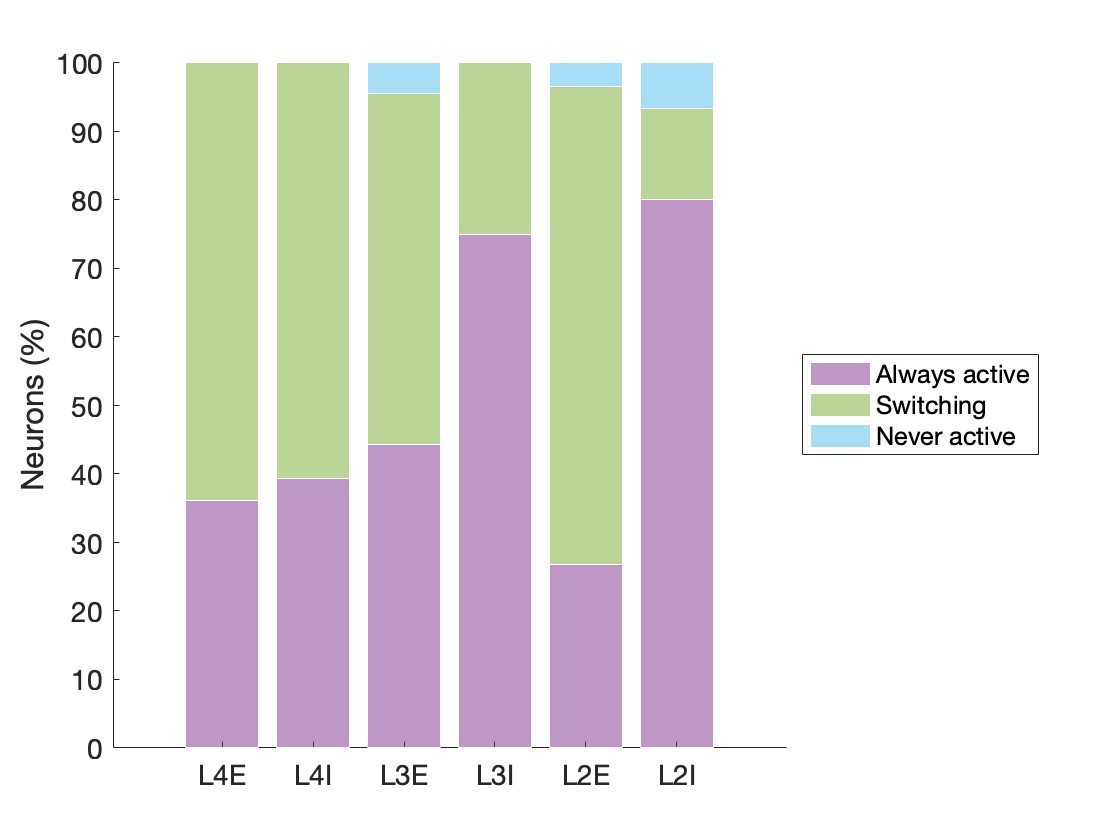

clearvars -except s_num synScalingFactors pconnScalingFactors Save* RandomSeeds AnalysisPath AdvancedAnalysis FiguresPath SaveAn_pre
load('Fig2_PlotDataParticipationInTime_perNeuron.mat')

ActivityAcrossConditions = [];
for pp = 1:size(mean_signals,3)
    IsActive = [];
    for neuron = 1:length(mean_signals{1,2,pp}) % neuron indices in mean_signals are not sorted!
        for cond = 1:size(mean_signals, 1)
            if any(mean_signals{cond,1,pp}{neuron,1}) 
                IsActive(cond,neuron) = 1;
            else
                IsActive(cond,neuron) = 0;
            end
        end
    end
    ActivityAcrossConditions{pp,1} = IsActive;
    ActivityAcrossConditions{pp,2} = mean_signals{1,3,pp}([1:3]);
%     ActivityAcrossConditions{pp,2} = mean_signals{1,2,pp}; % rank based on trial-to-trial participation
end

figure; clf; hold on;
colors = [0.4940 0.1840 0.5560; 0.4660 0.6740 0.1880; 0.3010 0.7450 0.9330];

for pp = 1:size(mean_signals,3)    
    %[always_active, switching, never_active]
    aa = numel(find(ismember(sum(ActivityAcrossConditions{pp, 1},1), 4)));
    sw = numel(find(ismember(sum(ActivityAcrossConditions{pp, 1},1), [1, 2, 3])));
    na = numel(find(ismember(sum(ActivityAcrossConditions{pp, 1},1), 0)));
    
    aa_idx = find(ismember(sum(ActivityAcrossConditions{pp, 1},1), 4));
    sw_idx = find(ismember(sum(ActivityAcrossConditions{pp, 1},1), [1, 2, 3]));
    na_idx = find(ismember(sum(ActivityAcrossConditions{pp, 1},1), 0));
    
    b = bar(pp, ([aa sw na]./size(ActivityAcrossConditions{pp, 1},2)).*100, 'stacked', 'facealpha', 0.5, 'facecolor', 'flat', 'edgecolor', [1 1 1]);

    % Set the colors for each segment
    for i = 1:length(find([aa sw na]>0))
        b(i).FaceColor = colors(i,:);
    end
end
ylim([0 100])
xax = gca;
xax.XTickMode = 'manual';
xax.XTick = 1:6;
xax.XTickLabel = ActivityAcrossConditions(:,2);
ylabel('Neurons (%)')
set(gca, 'fontsize', 14) 
ax=get(gca,'Children');
legend(flipud(ax([1:3])),'Always active', 'Switching', 'Never active', 'location', 'eastoutside')

Quantify directionality.

I have 4 conditions, therefore a vector with 4 elements, where each conditions is described with either active (1) or inactive (0) label. Every element, thus, can have 2 values. It follows that there are 2^4 = 16 possible combinations for this vector. Directionality is only relevant for neurons that switch, so I am not interested in combinations [1, 1, 1, 1] and [0, 0, 0, 0] because those are valid for always active and silent neurons, respectively. This leaves me with 14 other combinations. To write the directionality detection algorithm, I will just detect which vector patter a neuron shows. Then I will plot all. Here is a library of the 14 combinations:

- 0001

- 0010

- 0011

- 0100

- 0101

- 0110

- 0111

- 1000

- 1001

- 1010

- 1011

- 1100

- 1101

- 1110

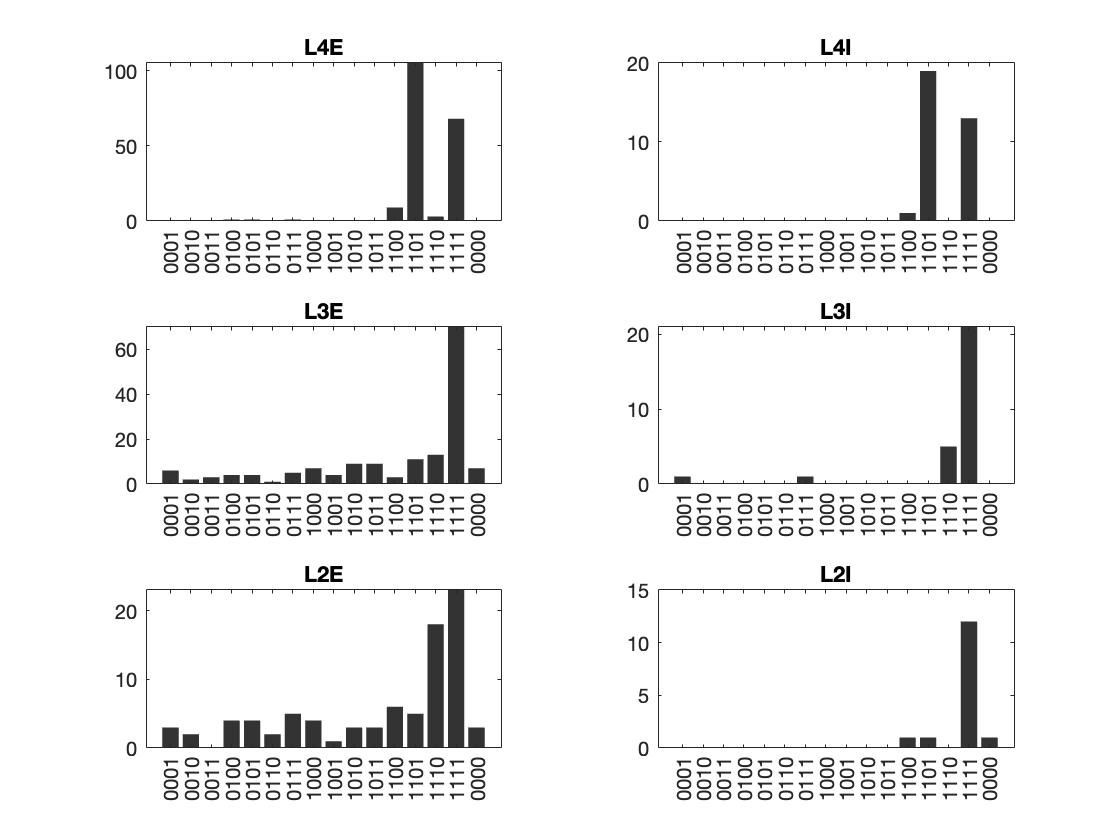

clearvars -except s_num synScalingFactors pconnScalingFactors Save* RandomSeeds AnalysisPath AdvancedAnalysis FiguresPath SaveAn_pre
load('Fig2_PlotDataParticipationInTime_perNeuron.mat')

Directionality = [];
AllActivityPatterns = [];
pops = flipud(['L2I';'L2E';'L3I';'L3E';'L4I';'L4E']);

for pp = 1:size(mean_signals,3)
    thisPop = mean_signals{1,3,pp}([1:3]);
    DirectionalityLibrary = [...
        {['0001']}, {[0,0,0,1]}, {[0]}, {[]};...
        {['0010']}, {[0,0,1,0]}, {[0]}, {[]};...
        {['0011']}, {[0,0,1,1]}, {[0]}, {[]};...
        {['0100']}, {[0,1,0,0]}, {[0]}, {[]};...
        {['0101']}, {[0,1,0,1]}, {[0]}, {[]};...
        {['0110']}, {[0,1,1,0]}, {[0]}, {[]};...
        {['0111']}, {[0,1,1,1]}, {[0]}, {[]};...
        {['1000']}, {[1,0,0,0]}, {[0]}, {[]};...
        {['1001']}, {[1,0,0,1]}, {[0]}, {[]};...
        {['1010']}, {[1,0,1,0]}, {[0]}, {[]};...
        {['1011']}, {[1,0,1,1]}, {[0]}, {[]};...
        {['1100']}, {[1,1,0,0]}, {[0]}, {[]};...
        {['1101']}, {[1,1,0,1]}, {[0]}, {[]};...
        {['1110']}, {[1,1,1,0]}, {[0]}, {[]};...
        {['1111']}, {[1,1,1,1]}, {[0]}, {[]};... % always active
        {['0000']}, {[0,0,0,0]}, {[0]}, {[]};... % silent
        ];
    IsActive = [];
    for neuron = 1:length(mean_signals{1,2,pp}) % neuron indices in mean_signals are not sorted!
        conds = [];
        for cond = 1:size(mean_signals, 1)
            IsActive{cond,neuron} = [];
            for event = 1:size(mean_signals{cond,1,pp}{neuron,2},1)
                if any(mean_signals{cond,1,pp}{neuron,2}(event,:)) 
                    IsActive{cond,neuron} = [IsActive{cond,neuron}; 1];
                else
                    IsActive{cond,neuron} = [IsActive{cond,neuron}; 0];
                end
            end
            conds{cond, 1} = mean_signals{cond,1,1}{1,3};
        end
        % directionality
        IsActive_any(:, neuron) = cell2mat(cellfun(@(x) any(x), IsActive(:,neuron), 'uniformoutput', 0));
        dirIdx = find(cell2mat(cellfun(@(x) isequal(x, IsActive_any(:, neuron)'), DirectionalityLibrary(:,2), 'uniformoutput', 0)));
        DirectionalityLibrary{dirIdx,3} = DirectionalityLibrary{dirIdx,3} + 1;
        DirectionalityLibrary{dirIdx,4} = [DirectionalityLibrary{dirIdx,4}, neuron];
    end
    Directionality{pp,1} = thisPop;
    Directionality{pp,2} = DirectionalityLibrary;
    Directionality{pp,3} = IsActive;
    Directionality{pp,4} = conds;
end

f100 = figure; clf; tiledlayout(3,2); hold on;
for pp = 1:size(Directionality,1)
    nexttile(pp)
    data = [];
    for dir_idx = 1:size(Directionality{1,2},1)
       data(1,dir_idx) =  Directionality{pp, 2}{dir_idx, 3};
    end
    b = bar(1:size(Directionality{1,2},1), data, 'facealpha', 0.8, 'facecolor', 'flat', 'edgecolor', 'none', 'facecolor', 'k');
    xax = gca;
    xax.XTickMode = 'manual';
    xax.XTick = 1:size(Directionality{1,2},1);
    xax.XTickLabel = DirectionalityLibrary(:,1);
    title(Directionality(pp,1))
end

## Figure 4f

Network analysis -- presynaptic neuron profiles.

clearvars -except s_num SaveFigures SaveAn_pre SaveFig_pre FiguresPath pops s_num SaveSim_pre AnalysisPath
cd '/Users/teatompos/Library/CloudStorage/GoogleDrive-t.tompos@neurophysiology.nl/.shortcut-targets-by-id/1f3yqxuDDFP_-nrGlSKbqcVC3RJJZZWTiWyK5Kl5x65maOi21i1OEIloSOR_UsCfsdiH2FbZf/Lab notebook Tea Tompoš/Thesis/Chapter 2 (The model)/Simulations/ParamSensitivity/Fixed_CTX_Seed'

synStrs = [1, 2];
pconns = [1, 2];
pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I'];

for synStr = synStrs
    for pconn = pconns
        for r_num = 1:10
            % load raw network
            load(sprintf('%s_S%i_P%i_Rep%i_Seed%i.mat', SaveSim_pre, round(synStr*100), round(pconn*100), r_num, s_num));
            
            % analyse individual neurons and their presynaptic partners
            for pp = 1:length(pops)
                thisPop = pops(pp);
                inspectedNeurons = inspectCellBehaviour(SpikingNetwork, thisPop, [0, 0], 'network');
                % sort
                for neuron_group = 1:length(inspectedNeurons.cell_idx)
                    neurons = inspectedNeurons.cell_idx{neuron_group};
                    if ~isempty(neurons)
                        for neuron = 1:neurons
                            neuron_idx = inspectedNeurons.cell_idx{neuron_group}(neuron);
                            
                            E_feedforward = any(ismember(inspectedNeurons.ExcPrevLayer_conns{3,1}, neuron_idx));
                            E_recurrent = any(ismember(inspectedNeurons.ExcSameLayer_conns{3,1}, neuron_idx));
                            I_feedforward = any(ismember(inspectedNeurons.InhPrevLayer_conns{3,1}, neuron_idx));
                            I_recurrent = any(ismember(inspectedNeurons.InhSameLayer_conns{3,1}, neuron_idx));
                        end
                    end
                end
            end
        end
    end
end

## Figure 3 - supplement

smoothing = 1.2;

clearvars -except s_num SaveFigures SaveAn_pre SaveFig_pre FiguresPath pops s_num SaveSim_pre AnalysisPath smoothing

pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I'];
synScalingFactors = [0.4:0.2:2.5];
pconnScalingFactors = [0.4:0.2:2.5];

figure(1); clf; tiledlayout(2,3)
cd(AnalysisPath)

popSequence = [5 3 1 6 4 2];

AUCdata = load('Fig2_PlotDataAUC.mat');
AUCdata = AUCdata.Fig2_PlotData;
Participation = load('Fig2_PlotDataParticipation.mat');
Participation = Participation.Fig2_PlotData;
saveNew = 0;

popNums = [86; 15; 158; 28; 188; 33];

% Define the colors
magenta = [1 0 1];
white = [1 1 1];
baby_blue = [0.54 0.81 0.94];

% Create a colormap
n = 256; % number of points
m = [linspace(magenta(1), white(1), ceil(n/2)), linspace(white(1), baby_blue(1), floor(n/2)); ...
     linspace(magenta(2), white(2), ceil(n/2)), linspace(white(2), baby_blue(2), floor(n/2)); ...
     linspace(magenta(3), white(3), ceil(n/2)), linspace(white(3), baby_blue(3), floor(n/2))]';

for popSeq = 1:length(popSequence)
    jj = popSequence(popSeq);
    plotData = [];
    pop = pops(jj,:);

    plotDataFlat_auc = AUCdata{1, popSeq} ./ max(max(AUCdata{1, popSeq}));  % 
    
    plotDataFlat_part = Participation{1, popSeq} ./ popNums(popSeq); % (N_participating / N_events) / N_total
    plotDataFlat_part = plotDataFlat_part ./ max(max(plotDataFlat_part));
    
    plotDataFlat = plotDataFlat_auc ./ plotDataFlat_part;
    plotDataFlat(isnan(plotDataFlat)) = 0;
    
    %%% TOTAL SPIKING
    nexttile(popSeq);
    plotDataFlat = imgaussfilt(plotDataFlat, smoothing);
    h = pcolor_fleur(pconnScalingFactors, synScalingFactors, plotDataFlat);%
    set(h, 'EdgeColor', 'none', 'AlphaData', ~isnan(plotDataFlat), 'facecolor', 'flat');
    cb = colorbar;
    % Apply the colormap
    colormap(flipud(m))
    caxis([-1 1]+1);
    title(pop)
    ylabel(cb,'AUC / Participation', 'Interpreter','none')

    xax = gca;
    xax.XTickMode = 'manual';
    xax.XTick = pconnScalingFactors;
    xax.XTickLabel = pconnScalingFactors;

    xax.YTickMode = 'manual';
    xax.YTick = synScalingFactors;
    xax.YTickLabel = synScalingFactors;
    xlabel('PConn scale')
    ylabel('SynStr scale')
end

## Additional analysis

Figure 3b replotted with sorting indices from 4e

return
% average correlations (single-neurons): BULK
clearvars -except s_num SaveFigures SaveAn_pre SaveFig_pre FiguresPath pops s_num SaveSim_pre AnalysisPath smoothing RandomSeeds

PlotIt = 1;
s_num = 49;

pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I'];

smoothing = 0.5;
newAnalysis = 0;

synStrs = [1, 2];
pconns = [1, 2];

XCLimits = [-60 0];
f2 = figure; clf; tiledlayout(3,2);

cols = [
    0 0 0;                   % Black
    0.9373  0.8157  0.6353;  % Lightish orange
    0.3882  0.3725  0.6353;  % Dark violet-blue
    1 0 1;                   % Magenta
];

if ~newAnalysis
    load('Fig2_PlotXCorrSingleNeuronResorted_MostActive');
else
    load('Fig2_PlotDataParticipationInTime_perNeuron.mat')
    Plotted = [];
end

caxLims = [...
    10, 10, 50, 50, 0.05;...
    20, 20, 80, 80, 0.18;...
    20, 20, 80, 80, 0.02;...
    25, 25, 100, 100, 0.15;...
    150, 150, 250, 250, 0.02;...
    100, 100, 150, 150, 0.1];

for pop = 1:length(pops)
    if PlotIt
        cd(FiguresPath)
        f1 = figure; clf; tiledlayout(3,2);
    end
    jj = 1;
    ThisPop = pops(pop,:);
    for synStr = synStrs
        if newAnalysis
            load(sprintf('%s_S%i_Seed%i_full.mat', SaveAn_pre, round(synStr*100), s_num))
        end
        for pconn = pconns
            if newAnalysis
                label = sprintf('%s_S%i_P%i_Rep', SaveSim_pre, round(synStr*100), round(pconn*100));
            
                tbl = SNN_analysed(strcmp(SNN_analysed.Population, ThisPop) & contains(SNN_analysed.SimulationLabel, label),:);
                
                XCarray = [XCLimits(1):tbl.PSTHBinSize{1,1}:XCLimits(2)];
                SigToPlot_single = [];
                for ii = 1:size(tbl,1) % go through simulations
                    SingleNeuronXCorr = tbl.SingleNeuronPSTH_XCorr{ii,1};
                    PopXCorr = tbl.PopulationPSTH_XCorr{ii,1};
                    
                    NeuronNum = size(SingleNeuronXCorr,1);
                    
                    % trim raw signals
                    LagsInMs = tbl.SingleNeuronPSTH_XCorrLags{ii,1}(1,:) * tbl.PSTHBinSize{ii,1};
                    
                    xLeft = find(ismember(LagsInMs,XCLimits(1)));
                    xRight = find(ismember(LagsInMs,XCLimits(2)));
                    LagsLimits = LagsInMs(:,xLeft:xRight);
                    
                    % select datapoints for plotting
                    IdxToPlot = find(ismember(LagsLimits,XCarray));
                    ZeroIdx = find(ismember(XCarray,0));
                    
                    TrimmedSignals_single = SingleNeuronXCorr(:,xLeft:xRight);
                    
                    % sort for maximal value
                    pp = find(cell2mat(cellfun(@(x) contains(x, ThisPop), {mean_signals{1,3,:}}, 'uniformoutput', 0)));    
                    SortIndices = mean_signals{jj,2,pp}; % indices from 4e
                    SingleNeuronXCorrSorted = TrimmedSignals_single(SortIndices,:);
                    SigToPlot_single(1:NeuronNum,1:length(IdxToPlot),ii) = SingleNeuronXCorrSorted(:,IdxToPlot);
                end
            else
                NeuronNum = size(Plotted{pop, jj},1);
                XCarray = -60:3:0;
                ZeroIdx = 21;
            end
            
            if PlotIt
                %%% single-neuron normalization
                figure(f1)
                nexttile(jj); hold on;
                
                if newAnalysis
                    SigToPlot_single(isnan(SigToPlot_single)) = 0;
                    PlotAll = nanmean(SigToPlot_single,3);
                    Plotted{pop, jj, 1} = PlotAll;
                    Plotted{pop, jj, 2} = SortIndices;
                else
                    PlotAll = Plotted{pop, jj, 1};
                    SortIndices = Plotted{pop, jj, 2};
                end
                
                if jj == 1
                    baseline = trapz(mean(PlotAll(:,1:ZeroIdx),2));
                end
                
                h = pcolor_fleur(-XCarray, 1:NeuronNum, imgaussfilt(PlotAll./baseline, smoothing)); 
                set(h, 'EdgeColor', 'none', 'facecolor', 'flat');
                                
                title([ThisPop '; S' num2str(synStr) ' // P' num2str(pconn)])
                ylim([1 NeuronNum])
                xlabel('Lag (ms)')
                ylabel('Neuron')
                cb = colorbar;
                ylabel(cb,'<CC>')
                caxis([0 caxLims(pop,end)])
                set(gca,'fontsize', 14)
                xlim([XCarray(end) -XCarray(1)])
                xax = gca;
                xax.YTickMode = 'manual';
                xax.YTick = 1:length(SortIndices);
                xax.YTickLabel = SortIndices;
                
                nexttile(5); hold on;
                SumYAxis = PlotAll(:,1:ZeroIdx);
                seShade(SumYAxis', 0.2, cols(jj,:), 1:NeuronNum)
                xlim([1 NeuronNum])
                ylabel('<CC (raw)>')
                set(gca,'fontsize', 14, 'ydir', 'reverse', 'xdir', 'reverse')
                view([270 -90])
                
                if newAnalysis
                    Plotted{pop, jj, 3} = SumYAxis';
                    Plotted{pop, jj, 4}= ThisPop;
                end
                
                figure(f2)
                nexttile(pop); hold on;
                title([ThisPop '; <CC>'])
                seShade(SumYAxis', 0.2, cols(jj,:), 1:NeuronNum)
                xlim([1 NeuronNum])
                ylabel('<CC raw>')
                set(gca,'fontsize', 14, 'ydir', 'reverse', 'xdir', 'reverse')
                view([270 -90])
            end
            jj = 1+jj;
        end
    end
    
    if SaveFigures
        cd(FiguresPath)
        figure(f1)
        f=gcf;
        set(f, 'paperorientation', 'landscape', 'renderer','painter')
        print(f, [SaveFig_pre 'XCorr_single_normToSingle_Resort_MostActive' num2str(s_num) '_' ThisPop], '-dpdf','-bestfit')
    end
end

if newAnalysis
    cd(AnalysisPath); save('Fig2_PlotXCorrSingleNeuronResorted_MostActive', 'Plotted','-v7.3')
end

if SaveFigures
    figure(f2)
    f=gcf;
    set(f, 'paperorientation', 'landscape', 'renderer','painter')
    print(f, [SaveFig_pre 'XCorr_single_NormToSelfAll_ResortMostActive_seed' num2str(s_num)], '-dpdf','-bestfit')
end

Figure 3b replotted with neuron identity indices from 4e

% average correlations (single-neurons): BULK
clearvars -except s_num SaveFigures SaveAn_pre SaveFig_pre FiguresPath pops s_num SaveSim_pre AnalysisPath smoothing RandomSeeds

PlotIt = 1;
s_num = 49;

pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I'];

smoothing = 0.5;
newAnalysis = 0;

synStrs = [1, 2];
pconns = [1, 2];

XCLimits = [-60 0];
f2 = figure; clf; tiledlayout(3,2);

cols = [
    0 0 0;                   % Black
    0.9373  0.8157  0.6353;  % Lightish orange
    0.3882  0.3725  0.6353;  % Dark violet-blue
    1 0 1;                   % Magenta
];

if ~newAnalysis
    load('Fig2_PlotXCorrSingleNeuronResorted_Identity');
else
    load('Fig2_PlotDataParticipationInTime_perNeuron.mat')
    Plotted = [];
end

caxLims = [...
    10, 10, 50, 50, 0.05;...
    20, 20, 80, 80, 0.18;...
    20, 20, 80, 80, 0.02;...
    25, 25, 100, 100, 0.15;...
    150, 150, 250, 250, 0.02;...
    100, 100, 150, 150, 0.1];

for pop = 1:length(pops)
    if PlotIt
        cd(FiguresPath)
        f1 = figure; clf; tiledlayout(3,2);
    end
    jj = 1;
    ThisPop = pops(pop,:);
    for synStr = synStrs
        if newAnalysis
            load(sprintf('%s_S%i_Seed%i_full.mat', SaveAn_pre, round(synStr*100), s_num))
        end
        for pconn = pconns
            if newAnalysis
                label = sprintf('%s_S%i_P%i_Rep', SaveSim_pre, round(synStr*100), round(pconn*100));
            
                tbl = SNN_analysed(strcmp(SNN_analysed.Population, ThisPop) & contains(SNN_analysed.SimulationLabel, label),:);
                
                XCarray = [XCLimits(1):tbl.PSTHBinSize{1,1}:XCLimits(2)];
                SigToPlot_single = [];
                for ii = 1:size(tbl,1) % go through simulations
                    SingleNeuronXCorr = tbl.SingleNeuronPSTH_XCorr{ii,1};
                    PopXCorr = tbl.PopulationPSTH_XCorr{ii,1};
                    
                    NeuronNum = size(SingleNeuronXCorr,1);
                    
                    % trim raw signals
                    LagsInMs = tbl.SingleNeuronPSTH_XCorrLags{ii,1}(1,:) * tbl.PSTHBinSize{ii,1};
                    
                    xLeft = find(ismember(LagsInMs,XCLimits(1)));
                    xRight = find(ismember(LagsInMs,XCLimits(2)));
                    LagsLimits = LagsInMs(:,xLeft:xRight);
                    
                    % select datapoints for plotting
                    IdxToPlot = find(ismember(LagsLimits,XCarray));
                    ZeroIdx = find(ismember(XCarray,0));
                    
                    TrimmedSignals_single = SingleNeuronXCorr(:,xLeft:xRight);
                    
                    % sort for maximal value
                    pp = find(cell2mat(cellfun(@(x) contains(x, ThisPop), {mean_signals{1,3,:}}, 'uniformoutput', 0)));
                    IsActive = [];
                    for neuron = 1:length(mean_signals{1,2,pp}) % neuron indices in mean_signals are not sorted!
                        for cond = 1:size(mean_signals, 1)
                            if any(mean_signals{cond,1,pp}(neuron,:)) 
                                IsActive(cond,neuron) = 1;
                            else
                                IsActive(cond,neuron) = 0;
                            end
                        end
                    end
                    aa_idx = find(ismember(sum(IsActive,1), 4));
                    sw_idx = find(ismember(sum(IsActive,1), [1, 2, 3]));
                    na_idx = find(ismember(sum(IsActive,1), 0));
                    
                    SortIndices = [aa_idx, sw_idx, na_idx];
                    SingleNeuronXCorrSorted = TrimmedSignals_single(SortIndices,:);
                    SigToPlot_single(1:NeuronNum,1:length(IdxToPlot),ii) = SingleNeuronXCorrSorted(:,IdxToPlot);
                end
            else
                NeuronNum = size(Plotted{pop, jj},1);
                XCarray = -60:3:0;
                ZeroIdx = 21;
            end
            
            if PlotIt
                %%% single-neuron normalization
                figure(f1)
                nexttile(jj); hold on;
                
                if newAnalysis
                    SigToPlot_single(isnan(SigToPlot_single)) = 0;
                    PlotAll = nanmean(SigToPlot_single,3);
                    Plotted{pop, jj, 1} = PlotAll;
                    Plotted{pop, jj, 2} = {aa_idx; sw_idx; na_idx};
                else
                    PlotAll = Plotted{pop, jj, 1};
                    aa_idx = Plotted{pop, jj, 2}{1};
                    sw_idx = Plotted{pop, jj, 2}{2};
                    na_idx = Plotted{pop, jj, 2}{3};
                    SortIndices = [aa_idx, sw_idx, na_idx];
                end
                
                if jj == 1
                    baseline = trapz(mean(PlotAll(:,1:ZeroIdx),2));
                end
                
                h = pcolor_fleur(-XCarray, 1:NeuronNum, imgaussfilt(PlotAll./baseline, smoothing)); 
                set(h, 'EdgeColor', 'none', 'facecolor', 'flat');
                                
                title([ThisPop '; S' num2str(synStr) ' // P' num2str(pconn)])
                ylim([1 NeuronNum])
                xlabel('Lag (ms)')
                ylabel('Neuron')
                cb = colorbar;
                ylabel(cb,'<CC>')
                caxis([0 caxLims(pop,end)])
                set(gca,'fontsize', 14)
                xlim([XCarray(end) -XCarray(1)])
                xax = gca;
                xax.YTickMode = 'manual';
                xax.YTick = 1:length(SortIndices);
                xax.YTickLabel = SortIndices;
                
                line([XCarray(end)-0.5 -XCarray(1)+0.5], [length(aa_idx) length(aa_idx)]+0.5, 'color','m', 'linewidth',1.2)
                line([XCarray(end)-0.5 -XCarray(1)+0.5], [length([aa_idx, sw_idx]) length([aa_idx, sw_idx])]+0.5, 'color','m', 'linewidth',1.2)
                
                nexttile(5); hold on;
                SumYAxis = PlotAll(:,1:ZeroIdx);
                seShade(SumYAxis', 0.2, cols(jj,:), 1:NeuronNum)
                xlim([1 NeuronNum])
                ylabel('<CC (raw)>')
                set(gca,'fontsize', 14, 'ydir', 'reverse', 'xdir', 'reverse')
                view([270 -90])
                
                if newAnalysis
                    Plotted{pop, jj, 3} = SumYAxis';
                    Plotted{pop, jj, 4} = ThisPop;
                end
                
                figure(f2)
                nexttile(pop); hold on;
                title([ThisPop '; <CC>'])
                seShade(SumYAxis', 0.2, cols(jj,:), 1:NeuronNum)
                xlim([1 NeuronNum])
                ylabel('<CC raw>')
                set(gca,'fontsize', 14, 'ydir', 'reverse', 'xdir', 'reverse')
                view([270 -90])
            end
            jj = 1+jj;
        end
    end
    
    if SaveFigures
        cd(FiguresPath)
        figure(f1)
        f=gcf;
        set(f, 'paperorientation', 'landscape', 'renderer','painter')
        print(f, [SaveFig_pre 'XCorr_single_normToSingle_Resort_Identity' num2str(s_num) '_' ThisPop], '-dpdf','-bestfit')
    end
end

if newAnalysis
    cd(AnalysisPath); save('Fig2_PlotXCorrSingleNeuronResorted_Identity', 'Plotted','-v7.3')
end

if SaveFigures
    figure(f2)
    f=gcf;
    set(f, 'paperorientation', 'landscape', 'renderer','painter')
    print(f, [SaveFig_pre 'XCorr_single_NormToSelfAll_ResortIdentity_seed' num2str(s_num)], '-dpdf','-bestfit')
end

# Other

## Gain modulation heatmaps

clearvars -except s_num SaveFigures SaveAn_pre SaveFig_pre FiguresPath pops s_num SaveSim_pre AnalysisPath smoothing

pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I'];
synScalingFactors = [0.4:0.2:2.5];
pconnScalingFactors = [0.4:0.2:2.5];
 
figure(1); clf; tiledlayout(2,3)
cd(AnalysisPath)

popSequence = [5 3 1 6 4 2];
newAnalysis = 0;

if newAnalysis
    Fig2_PlotData = [];
    saveNew = 1;
else
    load('Fig2_PlotData_normToVPM.mat')
    saveNew = 0;
end

for popSeq = 1:length(popSequence)
    jj = popSequence(popSeq);
    plotData = [];
    VPM_data = [];
    pop = pops(jj,:);

    if newAnalysis
        for synStr = synScalingFactors
            load(sprintf('%s_S%i_EventData_Seed%i.mat', SaveAn_pre, round(synStr*100), s_num))
            
            for pconn = pconnScalingFactors
                label = sprintf('%s_S%i_P%i_Rep', SaveSim_pre, round(synStr*100), round(pconn*100));
                tbl = quant(strcmp(quant.Population, pops(jj,:)) & contains(quant.SimulationLabel, label),:);
                dataPoints = [];
                allVPM_AUC = trapz(nanmean(cell2mat({tbl.EventData{1,1}.VPM_FR_participating}'),1));
                
                if any(contains(fieldnames(tbl.EventData{1,1}), 'CTX_FR_participating'))
                    dataPoints = trapz(nanmean(cell2mat({tbl.EventData{1,1}.CTX_FR_participating}'),1));
                else
                    dataPoints = NaN;
                end
                plotData{find(synScalingFactors==synStr),find(pconnScalingFactors==pconn)} = dataPoints;
                VPM_data{find(synScalingFactors==synStr),find(pconnScalingFactors==pconn)} = allVPM_AUC;
            end
        end
        plotDataFlat = cell2mat(plotData);
        VPM_data_flat = cell2mat(VPM_data);

        Fig2_PlotData{1,popSeq} = plotDataFlat;
        Fig2_PlotData{2,popSeq} = VPM_data_flat;
        
        plotDataFlat = plotDataFlat./VPM_data_flat; % normalize to the vpm auc;
    else
        plotDataFlat = Fig2_PlotData{1, popSeq};
        VPM_data_flat = Fig2_PlotData{2, popSeq};
        
        plotDataFlat = plotDataFlat./VPM_data_flat; % normalize to the max;
    end
  
    plotDataFlat(isnan(plotDataFlat)) = 0;
    
    %%% TOTAL SPIKING
    nexttile(popSeq);
    h = pcolor_fleur(pconnScalingFactors, synScalingFactors, imgaussfilt(plotDataFlat, 3.5)); %imgaussfilt(plotDataFlat, 1.5)
    set(h, 'EdgeColor', 'none', 'AlphaData', ~isnan(plotDataFlat), 'facecolor', 'flat');
    cb = colorbar;
    colormap(turbo(256));
    caxis([0, 3]);
    title(pop)
    ylabel(cb,'CTX_AUC / VPM_AUC', 'Interpreter','none')

    xax = gca;
    xax.XTickMode = 'manual';
    xax.XTick = pconnScalingFactors;
    xax.XTickLabel = pconnScalingFactors;

    xax.YTickMode = 'manual';
    xax.YTick = synScalingFactors;
    xax.YTickLabel = synScalingFactors;
    xlabel('PConn scale')
    ylabel('SynStr scale')
end
if saveNew
    cd(AnalysisPath); save('Fig2_PlotData_normToVPM', 'Fig2_PlotData','-v7.3')
end

% nexttile(1); caxis([0 1])
% nexttile(4); caxis([0 1])

cols = [
    0 0 0;                   % Black
    0.9373  0.8157  0.6353;  % Lightish orange
    0.3882  0.3725  0.6353;  % Dark violet-blue
    1 0 1;                   % Magenta
];

if SaveFigures
    cd(FiguresPath)
    for ii=1:6; nexttile(ii); hold on;
        scatter(1,1,28,'filled','markerfacecolor',cols(1,:),'markeredgecolor',[1 1 1]);
        scatter(2,1,28,'filled','markerfacecolor',cols(2,:),'markeredgecolor',[1 1 1]); 
        scatter(1,2,28,'filled','markerfacecolor',cols(3,:),'markeredgecolor',[1 1 1]); 
        scatter(2,2,28,'filled','markerfacecolor',cols(4,:),'markeredgecolor',[1 1 1]); 
    end
    f=gcf;
    set(f, 'paperorientation', 'landscape', 'renderer','painter')
    print(f,[SaveFig_pre '_heatmap_TotSpikes_normToVPM_seed' num2str(s_num)], '-dpdf','-bestfit')
end

## Gain modulation: individual cases

clearvars -except s_num synScalingFactors pconnScalingFactors Save* RandomSeeds AnalysisPath AdvancedAnalysis FiguresPath
synStrs = [1, 2];
pconns = [1, 2];

cols = [
    0 0 0;                   % Black
    0.9373  0.8157  0.6353;  % Lightish orange
    0.3882  0.3725  0.6353;  % Dark violet-blue
    1 0 1;                   % Magenta
];

pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I'];
mean_signals = [];

figure; clf; tiledlayout(1,6);

for pp = 1:length(pops)
    pop = pops(pp,:);
    
    jj = 1;
    legend_labels = [];
    for synStr = synStrs
        load(sprintf('%s_S%i_EventData_Seed%i.mat', SaveAn_pre, round(synStr*100), s_num))
        for pconn = pconns
            label = sprintf('%s_S%i_P%i_Rep', SaveSim_pre, round(synStr*100), round(pconn*100));
            tbl = quant(strcmp(quant.Population, pop) & contains(quant.SimulationLabel, label),:);
            
            % CTX FR (spikes/N(participating))
            nexttile(pp); hold on; 
            ctx_signal = {tbl.EventData{1,1}.CTX_FR_participating}';
            ctx_signal(cell2mat(cellfun(@(x) isempty(x), ctx_signal, 'UniformOutput',0))) = {nan(size(tbl.EventData{1,1}(1).VPM_hist))};

            legend_labels{end+1} = sprintf('S%0.1f_P%0.1f', synStr, pconn);

            % norm to VPM
            nexttile(pp); hold on;
            vpm_signal = {tbl.EventData{1,1}.VPM_FR_participating}';
            signal = cell2mat(cellfun(@(x, y) (x./y), ctx_signal, vpm_signal, 'UniformOutput',0));
            signal(isinf(signal)) = NaN;
            
            seShade(signal, 0.2, cols(jj,:), tbl.EventData{1,1}(1).hist_time(1:end-1))
            mean_signals{jj,1,pp} = nanmean(signal,1);
            
            mean_signals{jj,2,pp} = signal;

            jj = jj+1;
        end
    end
    nexttile(pp);
    title(pop)
    xlabel('Time (ms)')
    ylabel('FR (spikes / N)')
    set(gca, 'fontsize', 14)
    % title(sprintf('synStr: %.1f; pconn: %.1f', synStr, pconn))
    ax=get(gca,'Children');
    legend(flipud(ax([1:2:end])), legend_labels, 'Interpreter', 'none')
    ylim([0 30])
    
    if SaveFigures
        cd(FiguresPath)
        f=gcf;
        set(f, 'paperorientation', 'landscape', 'renderer','painter')
        print(f,[SaveFig_pre '_analysisExample_' pop '_seed' num2str(s_num)], '-dpdf','-bestfit')
    end
end

## Gain modulation: linearity

clearvars -except s_num synScalingFactors pconnScalingFactors Save* RandomSeeds AnalysisPath AdvancedAnalysis FiguresPath
synStrs = [1, 2];
pconns = [1, 2];

cols = [
    0 0 0;                   % Black
    0.9373  0.8157  0.6353;  % Lightish orange
    0.3882  0.3725  0.6353;  % Dark violet-blue
    1 0 1;                   % Magenta
];

pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I'];
mean_signals = [];
figure; clf; tiledlayout(1,6);

for pp = 1:length(pops)
    pop = pops(pp,:);
    
    jj = 1;
    legend_labels = [];
    for synStr = synStrs
        load(sprintf('%s_S%i_EventData_Seed%i.mat', SaveAn_pre, round(synStr*100), s_num))
        for pconn = pconns
            label = sprintf('%s_S%i_P%i_Rep', SaveSim_pre, round(synStr*100), round(pconn*100));
            tbl = quant(strcmp(quant.Population, pop) & contains(quant.SimulationLabel, label),:);
            
            % CTX FR (spikes/N(participating))
            nexttile(pp); hold on; 
            ctx_signal = {tbl.EventData{1,1}.CTX_FR_participating}';
            ctx_signal(cell2mat(cellfun(@(x) isempty(x), ctx_signal, 'UniformOutput',0))) = {nan(size(tbl.EventData{1,1}(1).VPM_hist))};

            legend_labels{end+1} = sprintf('S%0.1f_P%0.1f', synStr, pconn);

            % norm to VPM
            vpm_signal = {tbl.EventData{1,1}.VPM_FR_participating}';
            signal = cell2mat(cellfun(@(x, y) (x./y), ctx_signal, vpm_signal, 'UniformOutput',0));
            signal(isinf(signal)) = NaN;
            
            mean_signals{jj,1,pp} = nanmean(signal,1);
            mean_signals{jj,2,pp} = signal;

            jj = jj+1;
        end
    end
    
    nexttile(pp); hold on;
    title(pop)
    linearity = mean_signals{4, 1, pp} ./ (mean_signals{2, 1, pp} + mean_signals{3, 1, pp});
    plot(tbl.EventData{1,1}(1).hist_time(1:end-1),linearity)
    plot(xlim, [1 1], ':k', 'linewidth', 1.2)
    ylim([1-2 1+2])
    xlabel('Time (ms)')
    ylabel('Linearity C/(A+B)')
    set(gca, 'fontsize', 14)
    
    if SaveFigures
        cd(FiguresPath)
        f=gcf;
        set(f, 'paperorientation', 'landscape', 'renderer','painter')
        print(f,[SaveFig_pre '_analysisExampleL_' pop '_seed' num2str(s_num)], '-dpdf','-bestfit')
    end
end

# Addition to Figure 6 (from N4Model_Figure4.mlx)

The problem is that Figure 6a and b (in N4Model_Figure4.mlx) represent data from many randomized connectivity structures, while here I explore only one type of a random structure.

% single-neuron xcorr with population activity
clearvars -except s_num synScalingFactors pconnScalingFactors Save* RandomSeeds AnalysisPath AdvancedAnalysis FiguresPath SaveAn_pre

pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I'];
synStrs = [1, 2];
pconns = [1, 2];

newAnalysis = 0;
cols = [
    0 0 0;                   % Black
    0.9373  0.8157  0.6353;  % Lightish orange
    0.3882  0.3725  0.6353;  % Dark violet-blue
    1 0 1;                   % Magenta
];

if newAnalysis
    quant = [];
    saveNew = 1;
    
    for synStr = synStrs
        AnSaveName = sprintf('%s_S%i_Seed%i_full.mat', SaveAn_pre, round(synStr*100), s_num);
        load(AnSaveName)
        
        for pconn = pconns
            for jj=1:length(pops)
                label = sprintf('%s_S%i_P%i_Rep', SaveSim_pre, round(synStr*100), round(pconn*100));
                tbl = SNN_analysed(strcmp(SNN_analysed.Population, pops(jj,:)) & contains(SNN_analysed.SimulationLabel, label),:);
                
                for rep = 1:size(tbl,1)
                    for event = 1:tbl.VPMEventNum{rep,1}
                        st = tbl.VPMEventData{rep,1}{1, event}.PeakTime;
                        in = tbl.PSTHBinSize{rep,1};
                        en = tbl.VPMEventData{rep,1}{1, event}.PeakTime + 60;
                        
                        binEdges = [st:in:en];
                        populationPSTH = histcounts(cell2mat(tbl.SpikeTimes{rep,1}'), binEdges);
                        
                        allNeuronXCs = [];
                        allNeuronLags = [];
                        for neuron = 1:length(tbl.SpikeTimes{rep,1})
                            if ~isempty(tbl.SpikeTimes{rep,1}{1, neuron})
                                oneNeuronPSTH = histcounts(tbl.SpikeTimes{rep,1}{1, neuron}, binEdges);
                                [xc, l] = xcorr(populationPSTH, oneNeuronPSTH);
%                                 if any(xc>0)
%                                     xc = xc ./ trapz(xc); % normalize to its AUC
%                                 end
                                lags = l*in;
                            else
                                xc = zeros(1,length(populationPSTH)*2 - 1);
                                lags = -60+in:in:60-in;
                            end
                            allNeuronXCs{neuron, 1} = xc(1:find(lags == 0)); % take only the left part of the xcorr
                            allNeuronLags{neuron, 1} = lags(1:find(lags == 0));
                        end
                        quant = [quant; table(synStr, pconn, {pops(jj,:)}, rep, event, {allNeuronXCs}, {allNeuronLags}, 'VariableNames',{'synStr', 'pconn', 'pop', 'rep', 'event', 'xcorr', 'lags'})];
                    end
                end
            end
        end
    end
else
    load('Fig2_PlotDataSelfPopXCorr.mat')
    saveNew = 0;
end

if saveNew
   cd(AnalysisPath); save('Fig2_PlotDataSelfPopXCorr', 'quant','-v7.3')
end

% plot per pop
f2 = figure; clf; tiledlayout(3,2)
for jj = 1:length(pops)
    f1 = figure; clf; tiledlayout(2,2)
    kk = 1;
    for synStr = synStrs
        for pconn = pconns
            minitbl = quant(strcmp(quant.pop, pops(jj,:)) & ismember(quant.synStr, synStr) & ismember(quant.pconn, pconn) , :);
            
            SingleNeuronXCorrSorted = [];
            for event = 1:size(minitbl,1)
                xcorrData = cell2mat(minitbl.xcorr{event,1});
                
                % sort per max xcorr
                MaxXCorr = max(xcorrData,[],2);
                [~, SortIndices] = sort(MaxXCorr, 'descend');
                SingleNeuronXCorrSorted(1:size(xcorrData,1), 1:size(xcorrData,2), event) = xcorrData(SortIndices,:);
            end
            if kk == 1
                baseline = trapz(mean(nanmean(SingleNeuronXCorrSorted,3),2));
            end
            
            % then average across all
            figure(f1)
            nexttile;
            h = pcolor_fleur(minitbl.lags{1,1}{1, 1}, 1:length(minitbl.lags{1,1}), imgaussfilt(nanmean(SingleNeuronXCorrSorted,3)./baseline, 5.5));
            set(h, 'EdgeColor', 'none', 'facecolor', 'flat');
            
            title([pops(jj,:) '; S' num2str(synStr) ' // P' num2str(pconn)])
            xlabel('Lag (ms)')
            ylabel('Neuron')
            cb = colorbar;
            ylabel(cb,'<CC>')
%             caxis([0 0.05])
            set(gca,'fontsize', 14)
            
            figure(f2)
            nexttile(jj); hold on;
            title(pops(jj,:))
            seShade(nanmean(SingleNeuronXCorrSorted,3)', 0.2, cols(kk,:), 1:size(SingleNeuronXCorrSorted,1))
            xlim([1 size(SingleNeuronXCorrSorted,1)])
%             ylim([0 0.05])
            ylabel('<CC>')
            set(gca,'fontsize', 14, 'ydir', 'reverse', 'xdir', 'reverse')
            view([270 -90])
            kk = kk+1;
        end
    end
    if SaveFigures
        cd(FiguresPath)
        f=gcf;
        set(f, 'paperorientation', 'landscape', 'renderer','painter')
        print(f,[SaveFig_pre '_XCorrWithSelfPop_' pops(jj,:) '_seed' num2str(s_num)], '-dpdf','-bestfit')
    end
end

# Some helper code

return
% intermediate exploration
figure; tiledlayout(11,11)

jj = 5;
plotData = [];
pop = pops(jj,:);

for synStr = synScalingFactors
    load(sprintf('%s_S%i_EventFunctionFitting.mat', SaveAn_pre, round(synStr*100)))
    
    for pconn = pconnScalingFactors
        label = sprintf('%s_S%i_P%i_Rep', SaveSim_pre, round(synStr*100), round(pconn*100));
        tbl = quant(strcmp(quant.Population, pops(jj,:)) & contains(quant.SimulationLabel, label),:);
        if ~isempty(tbl.EventFitting{1,1})
            if any(contains({tbl.EventFitting{1,1}.SimulationLabel}', 'Combined'))
                signal = tbl.EventFitting{1,1}(end).FR_participating;
                time = tbl.EventFitting{1,1}(end).FR_participating_time(1:end-1);
                
                nexttile;
                stdShade(signal, 0.2, 'k', time)
                title(sprintf('S%i_P%i', round(synStr*100), round(pconn*100)), 'Interpreter', 'none')
                ylim([0 400])
            else
                nexttile;
                title(sprintf('S%i_P%i', round(synStr*100), round(pconn*100)), 'Interpreter', 'none')
                ylim([0 400])
            end
        else
            nexttile;
            title(sprintf('S%i_P%i', round(synStr*100), round(pconn*100)), 'Interpreter', 'none')
            ylim([0 400])
        end
    end
end

return

% This code inspects individual networks
clear SpikingNetwork inspection pop

synStr = 2;
pconn = 1.2;
r_num = 6;
NetSaveName = sprintf('%s_S%i_P%i_Rep%i_Seed%i', SaveSim_pre, round(synStr*100), round(pconn*100), r_num, s_num);
load(NetSaveName)
fprintf('Loaded %s.mat\n', NetSaveName)

pop = 'L4I';
inspection = inspectCellBehaviour(SpikingNetwork, pop, [0 0], []);

fns_idx = inspection.cell_idx{1}
fs_idx = inspection.cell_idx{2}

figure; clf; hold on;
for ii = 1:size(SpikingNetwork.([pop '_V']),2)
    yIncrement = ii * 80;
    if ismember(ii, [fns_idx, fs_idx])
        plot(SpikingNetwork.time, SpikingNetwork.([pop '_V'])(:,ii) + yIncrement, 'r')
    else
        plot(SpikingNetwork.time, SpikingNetwork.([pop '_V'])(:,ii) + yIncrement, 'k')
    end
end
plot([100 100], ylim, ':r', 'linewidth', 2)
ylabel('Neurons (stacked)')
xlabel('Time (ms)')
set(gca, 'fontsize', 14, 'yticklabel',[])
title(['Activity of ' pop ' in ' NetSaveName '.'], 'interpreter', 'none')

SNN_indivitual = analyzeSim(SpikingNetwork, NetSaveName, 0, 'threshold');
fprintf('Nans detected: %i.\n', size(SpikingNetwork.([pop '_V']),2)-sum([numel(fns_idx) numel(fs_idx) numel(inspection.cell_idx{3})]))

figure; clf; hold on;
bar(1,numel(fns_idx),'EdgeColor','none', 'facecolor','k','facealpha',0.1)
bar(2,numel(fs_idx),'EdgeColor','none', 'facecolor','b','facealpha',0.2)
bar(3,numel(inspection.cell_idx{3}),'EdgeColor','none', 'facecolor','g','facealpha',0.2)
set(gca,'fontsize',16, 'xticklabel', [])
legend_labels('FNS', 'FS', 'HT', 'location', 'northwest')
ylabel('Cell count')